# Retinal Area Comparisons

## Humans: Initialize Variables

clear all
addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

species='Humans';

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 3; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','V7','LO1','LO2','TO1','TO2'};
allparietal_numbers=1:7;
allparietal_labels={'IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};
allfrontal_numbers=1:2;
allfrontal_labels={'FEF','IFS'};
% allLGN_numbers = 1;
% allLGN_labels={'LGN'};

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_human=1:6; EVCcolor=[0 0 0.7];
V4rois_human=7; V4color=[0.6 0 0.6];
ventralrois_human=8:11; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=12:14; dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralrois_human=15:18; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=19:25; parietalcolor=[0 0.7 0.7];
frontalrois_human=26:27; frontalcolor=[.4 0 .4];
% LGNrois=28; LGNcolor=[1 1 0];

% concatenate all human area ROIs, labels, and colors
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human;frontalrois_human};%LGNrois};
alllabels_human=[allvisual_labels, allparietal_labels, allfrontal_labels];%, allLGN_labels];
use_colorscale_human=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,length(dorsalrois_human),1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1);...
    repmat(frontalcolor,length(frontalrois_human),1)];
%     repmat(LGNcolor,1,1)];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human = flipud(use_colorscale_human);

nodearea_smoothwm_col=2;
nodearea_pial_col=3;

allrois_human{4} = allrois_human{4}(1:2);allrois_human{5} = allrois_human{5}-1;allrois_human{6} = allrois_human{6}-1;allrois_human{7} = allrois_human{7}-1;

load('allhumandata.mat')

## Humans: Extract Data from Files

% % This should be a more efficient way of filtering the directories:
% files = dir(data_dir);
% names = {files.name}; 
% dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
% subjs=names(dirFlags);
% norois=[];
% 
% % retino_surfacearea outputs are 1x2 cells (R&L hemispheres) each 18x62 (brain area x
% % subject), total_surfacearea is sum of all brain areas 1x2 cell each 1x62.
% % parietal, frontal and LGN have similar structure
% [retino_surfacearea_total,retino_surfacearea_smoothwm,retino_surfacearea_pial,...
%     parietal_surfacearea_total,parietal_surfacearea_smoothwm,parietal_surfacearea_pial,...
%     frontal_surfacearea_total,frontal_surfacearea_smoothwm,frontal_surfacearea_pial,...
%     LGN_surfacearea] = getSubjData_human(subjs,species,plot_indiv_subj,...
%     allvisual_numbers,allparietal_numbers,allfrontal_numbers,nodearea_smoothwm_col,nodearea_pial_col);
% humandata = struct;
% humandata.retino_surfacearea_total = retino_surfacearea_total;
% humandata.retino_surfacearea_smoothwm = retino_surfacearea_smoothwm;
% humandata.retino_surfacearea_pial = retino_surfacearea_pial;
% humandata.parietal_surfacearea_total = parietal_surfacearea_total;
% humandata.parietal_surfacearea_smoothwm = parietal_surfacearea_smoothwm;
% humandata.parietal_surfacearea_pial = parietal_surfacearea_pial;
% humandata.frontal_surfacearea_total = frontal_surfacearea_total;
% humandata.frontal_surfacearea_smoothwm = frontal_surfacearea_smoothwm;
% humandata.frontal_surfacearea_pial = frontal_surfacearea_pial;
% humandata.LGN_surfacearea = LGN_surfacearea;
% save('allhumandata.mat','humandata')

## Humans: Calculate Averages Based on Metric

% calculate sum of retinal, parietal, and frontal areas
for i = 1:2
    surfacearea_total{i} = humandata.retino_surfacearea_total{i} + humandata.parietal_surfacearea_total{i} + humandata.frontal_surfacearea_total{i};
    surfacearea_smoothwm{i} = [humandata.retino_surfacearea_smoothwm{i};humandata.parietal_surfacearea_smoothwm{i};humandata.frontal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [humandata.retino_surfacearea_pial{i};humandata.parietal_surfacearea_pial{i};humandata.frontal_surfacearea_pial{i}];
end
% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% concatenate LGN surface area
% surfacearea_avg{1} = [surfacearea_avg{1};LGN_surfacearea{1}];
% surfacearea_avg{2} = [surfacearea_avg{2};LGN_surfacearea{2}];

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_human = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_human = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_human = surfacearea_avg;
end

% remove V7
surfacearea_human{1}(14,:) = [];surfacearea_human{2}(14,:) = [];

## Humans: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = surfacearea_bothhemis(7,:);

v_human = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;surfacearea_bothhemis(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_combined_human = mean(v_human(ventralrois_human-3,:),1);
dorsal_combined_human = mean(v_human(dorsalrois_human(1:2)-3,:),1);
lateral_combined_human = mean(v_human(lateralrois_human-3,:),1);
parietal_combined_human = mean(v_human(parietalrois_human-3,:),1);
frontal_combined_human = mean(v_human(frontalrois_human-3,:),1);
% LGN_combined_human = mean(v_human(LGNrois-3,:),1);

v_combined_human = [v_human(1:4,:);ventral_combined_human;dorsal_combined_human;...
    lateral_combined_human;parietal_combined_human;frontal_combined_human];%LGN_combined_human];

%combined hemis V1
normv1_human = v_human./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normventral_combined_human = mean(normv1_human(ventralrois_human-3,:),1);
normdorsal_combined_human = mean(normv1_human(dorsalrois_human(1:2)-3,:),1);
normlateral_combined_human = mean(normv1_human(lateralrois_human-3,:),1);
normparietal_combined_human = mean(normv1_human(parietalrois_human-3,:),1);
normfrontal_combined_human = mean(normv1_human(frontalrois_human-3,:),1);
% normLGN_combined_human = mean(normv1_human(LGNrois-3,:),1);

normv1_combined_human = [normv1_human(1:4,:);normventral_combined_human;normdorsal_combined_human;...
    normlateral_combined_human;normparietal_combined_human;normfrontal_combined_human];%normLGN_combined_human];

use_colorscale_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];%LGNcolor];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human = flipud(use_colorscale_human);

alllabels_humans_general = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal','Frontal'};%,'LGN'};


## Monkeys: Initialize Variables

species='Monks';

plot_indiv_subj=0; % turn on/off single subject graphs
area_metric = 1; %1-smoothwm, 2-pial, 3-avg

data_dir = ['.\', num2str(species)];
% addpath(genpath(data_dir))
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,100,101,102,103,52,53,54,55,56];
alllabels_monkey={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_monkey=1:6; EVCcolor=[0.1 0.6 1];
V4rois_monkey=7:10; V4color=[1 0.2 1];
ventralrois_monkey=11:15; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=16:17; dorsalcolor=[1 .8 0];
lateralrois_monkey=18:21; lateralcolor=[0 1 0];
parietalrois_monkey=22:26; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
allrois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
use_colorscale_monkey=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1);...
    repmat(frontalcolor,length(frontalrois_human),1)];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');

load('allmonkeydata.mat')

## Monkeys: Extract Data from Files

% This should be a more efficient way of filtering the directories:
% files = dir(data_dir);
% names = {files.name}; 
% dirFlags = [files.isdir] & ~strcmp(names, '.') & ~strcmp(names, '..') & ~strcmp(names, 'phasemaps') & ~strcmp(names, 'VTPM') & ~strcmp(names, 'VTPM_delayedsaccade') & ~strcmp(names, 'MNI') & ~strcmp(names, 'ignore');
% subjs=names(dirFlags);
% norois=[];
% 
% % same structure as human data
% [retino_surfacearea_total,retino_surfacearea_smoothwm,retino_surfacearea_pial] = getSubjData( ...
%     subjs,species,plot_indiv_subj,allvisual_numbers,nodearea_smoothwm_col,nodearea_pial_col);
% 
% monkeydata = struct;
% monkeydata.retino_surfacearea_total = retino_surfacearea_total;
% monkeydata.retino_surfacearea_smoothwm = retino_surfacearea_smoothwm;
% monkeydata.retino_surfacearea_pial = retino_surfacearea_pial;
% save('allmonkeydata.mat','monkeydata')

## Monkeys: Calculate Averages Based on Metric

% rename areas to match human code
for i = 1:2
    surfacearea_total{i} = monkeydata.retino_surfacearea_total{i};
    surfacearea_smoothwm{i} = monkeydata.retino_surfacearea_smoothwm{i};
    surfacearea_pial{i} = monkeydata.retino_surfacearea_pial{i};
end
% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end
% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% get sum and concatenated hemispheres depending on area metric
if area_metric == 1
    % use this for WM 
    surfacearea_bothhemis = surfacearea_smoothwm{1} + surfacearea_smoothwm{2};
    surfacearea_catbothhemis=cat(2,surfacearea_smoothwm{1},surfacearea_smoothwm{2});
    surfacearea_monkey = surfacearea_smoothwm;
elseif area_metric ==2
    % use this for pial 
    surfacearea_bothhemis = surfacearea_pial{1} + surfacearea_pial{2};
    surfacearea_catbothhemis=cat(2,surfacearea_pial{1},surfacearea_pial{2});
    surfacearea_monkey = surfacearea_pial;
elseif area_metric == 3
    % use this for average of WM and pial surface
    surfacearea_catbothhemis = cat(2,surfacearea_avg{1},surfacearea_avg{2});
    surfacearea_bothhemis = surfacearea_avg{1} + surfacearea_avg{2};
    surfacearea_monkey = surfacearea_avg;
end


## Monkeys: Set Up Categories of Regions

mean_areas_bothhemis = nanmean(surfacearea_bothhemis,2); %take average for each visual area across subject 
stderror_areas_bothhemis = nanstd(surfacearea_bothhemis,0,2) / sqrt(size(surfacearea_bothhemis,1)); %find SE of surface area size for visual areas

% restructure data to get area categories we want to display
V1_bothhemis_combined = surfacearea_bothhemis(1,:) + surfacearea_bothhemis(2,:);
V2_bothhemis_combined = sum(surfacearea_bothhemis(3:4,:),1);
V3_bothhemis_combined = sum(surfacearea_bothhemis(5:6,:),1);
V4_bothhemis_combined = sum(surfacearea_bothhemis(7:8,:),1);
V4A_bothhemis_combined = sum(surfacearea_bothhemis(9:10,:),1);

v_monkey = [V1_bothhemis_combined;V2_bothhemis_combined;...
    V3_bothhemis_combined;V4_bothhemis_combined;V4A_bothhemis_combined;surfacearea_bothhemis(11:end,:)];

% average over broad areas for raw surface area measurements
V4_combined_monkey = mean(v_monkey(4:5,:),1);
ventral_combined_monkey = mean(v_monkey(ventralrois_monkey-5,:),1);
dorsal_combined_monkey = mean(v_monkey(dorsalrois_monkey-5,:),1);
lateral_combined_monkey = mean(v_monkey(lateralrois_monkey-5,:),1);
parietal_combined_monkey = mean(v_monkey(parietalrois_monkey-5,:),1);

v_combined_monkey = [v_monkey(1:3,:);V4_combined_monkey;ventral_combined_monkey;...
    dorsal_combined_monkey;lateral_combined_monkey;parietal_combined_monkey];

%combined hemis V1
normv1_monkey = v_monkey./V1_bothhemis_combined;

% average over broad regions for surface area measurements relative to V1
normV4_combined_monkey = mean(normv1_monkey(4:5,:),1);
normventral_combined_monkey = mean(normv1_monkey(ventralrois_monkey-5,:),1);
normdorsal_combined_monkey = mean(normv1_monkey(dorsalrois_monkey-5,:),1);
normlateral_combined_monkey = mean(normv1_monkey(lateralrois_monkey-5,:),1);
normparietal_combined_monkey = mean(normv1_monkey(parietalrois_monkey-5,:),1);

normv1_combined_monkey = [normv1_monkey(1:3,:);normV4_combined_monkey;normventral_combined_monkey;...
    normdorsal_combined_monkey;normlateral_combined_monkey;normparietal_combined_monkey];

use_colorscale_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');
use_colorscale_inv_monkey = flipud(use_colorscale_monkey);

alllabels_monkey = {'V1','V2','V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       
alllabels_monkeys_general = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_combined = {'V1','V1','V2','V2','V3','V3','V4','V4','Ventral','Ventral','Dorsal','Dorsal','Lateral','Lateral','Parietal','Parietal','Frontal','','LGN'};

## Fig 2A: Plot Raw Surface Area Comparisons

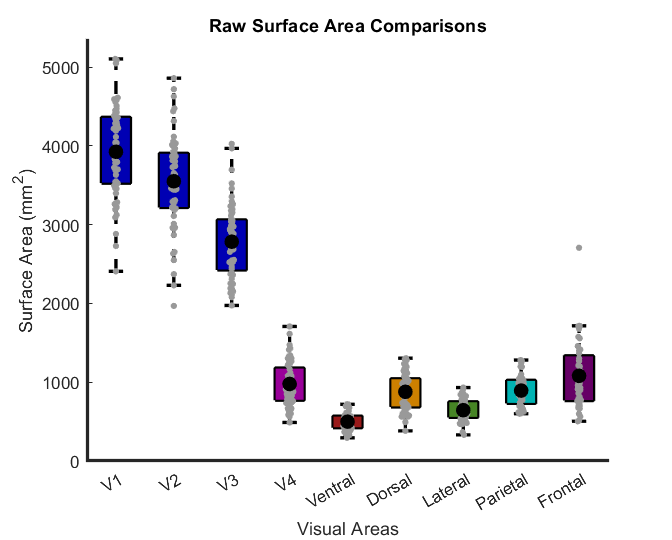

figure
hold on
h1=boxplot(v_combined_human','positions',1:2:size(v_combined_human,1)*2,'notch','off','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(v_combined_human,1)
   patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_inv_human(j,:),'FaceAlpha',1);
end
plotSpread(v_combined_human','xValues',1:2:size(v_combined_human,1)*2,'distributionColors',use_colorscale_human*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(v_combined_human,1)*2,nanmean(v_combined_human'),'k.','MarkerSize',30);
% xlim([0.5 size(normv1_combined_human,1)+.5])

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:2:length(alllabels_humans_general)*2],'xticklabel', alllabels_humans_general,'ytick',0:1000:5000);
xlabel('Visual Areas');
ylabel('Surface Area (mm^2)');
title('Raw Surface Area Comparisons')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

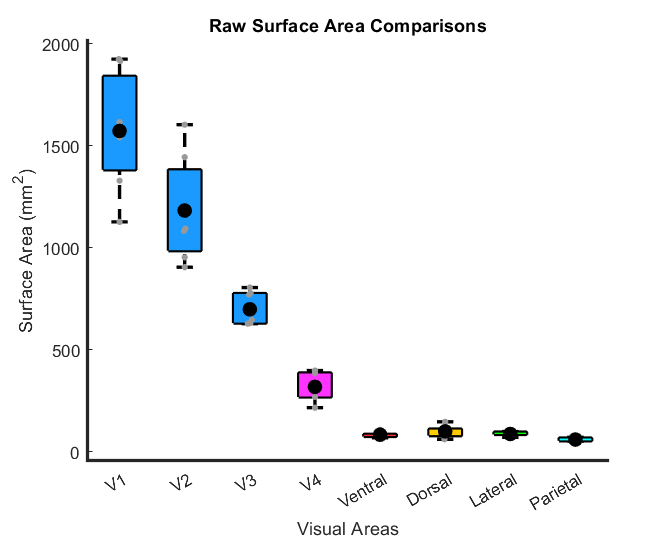



figure
hold on
h2=boxplot(v_combined_monkey','positions',1:2:size(v_combined_monkey,1)*2,'notch','off','colors',[0 0 0],'symbol','');
set(h2,{'linew'},{2})
h2 = findobj(gca,'Tag','Box');
for j=1:size(v_combined_monkey,1)
   patch(get(h2(j),'XData'),get(h2(j),'YData'),use_colorscale_inv_monkey(j+1,:),'FaceAlpha',1);
end
plotSpread(v_combined_monkey','xValues',1:2:size(v_combined_monkey,1)*2,'distributionColors',use_colorscale_monkey(1:end-1,:)*0+[.6 .6 .6],'spreadWidth',.5)
plot(1:2:size(v_combined_monkey,1)*2,nanmean(v_combined_monkey'),'k.','MarkerSize',30);
hold on

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',[1:2:length(alllabels_monkeys_general)*2],'xticklabel', alllabels_monkeys_general,'ytick',0:500:2000);
xlabel('Visual Areas');
ylabel('Surface Area (mm^2)');
title('Raw Surface Area Comparisons')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

## Fig 2B: Plot Normalized Surface Area Comparisons

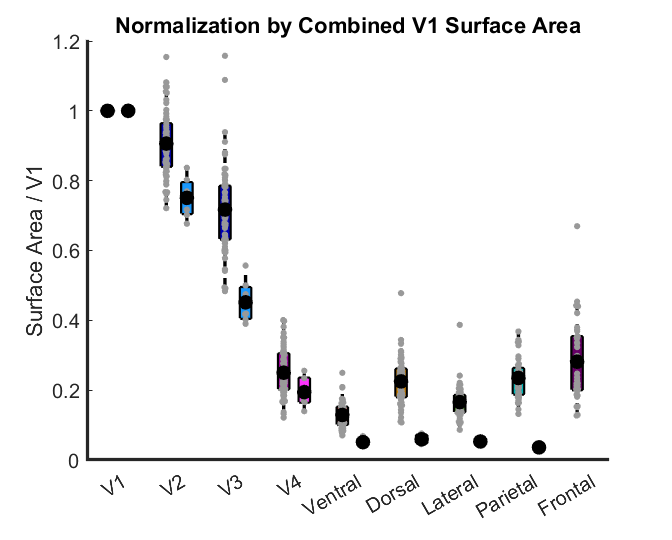

% pad array with nan to get the same size as humans
addnanmonkey = padarray(normv1_combined_monkey,[1 size(normv1_combined_human,2) - size(normv1_combined_monkey,2)],nan,'post');
concat_data = [];
concat_colorscale = [];
for i = 1:size(normv1_combined_human,1)
    concat_data = [concat_data; normv1_combined_human(i,:); addnanmonkey(i,:)];
    concat_colorscale = [concat_colorscale;use_colorscale_inv_monkey(i,:);use_colorscale_inv_human(i,:)];
end

% set groupings by species and areas to use factorgap in boxplot
g1 = sort([1:9,1:9]);
g2 = repmat(1:2,[1,9]);

figure
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabels_combined(1:2:end),'fontsize',12);
% xlabel('Visual Areas');
ylabel('Surface Area / V1');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 1.2])

pngFileName = ('Normalization_CombinedV1_Spaced.png');
fullFileName = fullfile(save_folder, pngFileName);
% saveas(gcf, fullFileName);

## Table of area sizes - raw and normalized to V1

% Human values
alllabels_human_merge = {'V1','V2','V3','V4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2','IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1','FEF','IFS'};
array_labels = {'Mean','SE','Min','Max','Mean Norm','SE Norm','Min Norm','Max Norm'};

concat_bothhemi_human = [surfacearea_human{1} surfacearea_human{2}];
surfacearea_human_merge = nan(length(alllabels_human_merge),size(concat_bothhemi_human,2));
surfacearea_human_merge(1,:) = concat_bothhemi_human(1,:)+concat_bothhemi_human(2,:);
surfacearea_human_merge(2,:) = concat_bothhemi_human(3,:)+concat_bothhemi_human(4,:);
surfacearea_human_merge(3,:) = concat_bothhemi_human(5,:)+concat_bothhemi_human(6,:);
surfacearea_human_merge(4:end,:) = concat_bothhemi_human(7:end,:);

surfacearea_human_merge_norm = surfacearea_human_merge./surfacearea_human_merge(1,:);

array_of_values_human = nan(size(surfacearea_human_merge,1),8);
array_of_values_human(:,1) = mean(surfacearea_human_merge,2,'omitnan');
array_of_values_human(:,2) = std(surfacearea_human_merge,[],2,'omitnan')/sqrt(size(surfacearea_human_merge,2));
array_of_values_human(:,3) = min(surfacearea_human_merge,[],2,'omitnan');
array_of_values_human(:,4) = max(surfacearea_human_merge,[],2,'omitnan');

array_of_values_human(:,5) = mean(surfacearea_human_merge_norm,2,'omitnan');
array_of_values_human(:,6) = std(surfacearea_human_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_human_merge_norm,2));
array_of_values_human(:,7) = min(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,8) = max(surfacearea_human_merge_norm,[],2,'omitnan');
array_of_values_human(:,1:4) = round(array_of_values_human(:,1:4),2);
array_of_values_human(:,5:8) = round(array_of_values_human(:,5:8),4);

table_of_values_human = array2table(array_of_values_human,'VariableNames',array_labels,'RowNames',alllabels_human_merge);

% Monkey values
alllabels_monkey_merge = {'V1','V2','V3','V4','V4A','OTd','PIT','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};

concat_bothhemi_monkey = [surfacearea_monkey{1} surfacearea_monkey{2}];
surfacearea_monkey_merge = nan(length(alllabels_monkey_merge),size(concat_bothhemi_monkey,2));
surfacearea_monkey_merge(1,:) = concat_bothhemi_monkey(1,:)+concat_bothhemi_monkey(2,:);
surfacearea_monkey_merge(2,:) = concat_bothhemi_monkey(3,:)+concat_bothhemi_monkey(4,:);
surfacearea_monkey_merge(3,:) = concat_bothhemi_monkey(5,:)+concat_bothhemi_monkey(6,:);
surfacearea_monkey_merge(4,:) = concat_bothhemi_monkey(7,:)+concat_bothhemi_monkey(8,:);
surfacearea_monkey_merge(5,:) = concat_bothhemi_monkey(9,:)+concat_bothhemi_monkey(10,:);
surfacearea_monkey_merge(6,:) = concat_bothhemi_monkey(11,:);
surfacearea_monkey_merge(7,:) = concat_bothhemi_monkey(12,:)+concat_bothhemi_monkey(13,:);
surfacearea_monkey_merge(8:end,:) = concat_bothhemi_monkey(14:end,:);

surfacearea_monkey_merge_norm = surfacearea_monkey_merge./surfacearea_monkey_merge(1,:);

array_of_values_monkey = nan(size(surfacearea_monkey_merge,1),8);
array_of_values_monkey(:,1) = mean(surfacearea_monkey_merge,2,'omitnan');
array_of_values_monkey(:,2) = std(surfacearea_monkey_merge,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge,2));
array_of_values_monkey(:,3) = min(surfacearea_monkey_merge,[],2,'omitnan');
array_of_values_monkey(:,4) = max(surfacearea_monkey_merge,[],2,'omitnan');

array_of_values_monkey(:,5) = mean(surfacearea_monkey_merge_norm,2,'omitnan');
array_of_values_monkey(:,6) = std(surfacearea_monkey_merge_norm,[],2,'omitnan')/sqrt(size(surfacearea_monkey_merge_norm,2));
array_of_values_monkey(:,7) = min(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,8) = max(surfacearea_monkey_merge_norm,[],2,'omitnan');
array_of_values_monkey(:,1:4) = round(array_of_values_monkey(:,1:4),2);
array_of_values_monkey(:,5:8) = round(array_of_values_monkey(:,5:8),4);

table_of_values_monkey = array2table(array_of_values_monkey,'VariableNames',array_labels,'RowNames',alllabels_monkey_merge);

## Correlation Matrix Across All Areas - Human & Monkey

all_area_corr_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        include = ~isnan(surfacearea_human_merge(i,:)) & ~isnan(surfacearea_human_merge(j,:));
        [r,p] = corr(surfacearea_human_merge(i,include)',surfacearea_human_merge(j,include)');
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
all_area_pval_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
for i = 1:length(alllabels_monkey_merge)
    for j = 1:length(alllabels_monkey_merge)
        include = ~isnan(surfacearea_monkey_merge(i,:)) & ~isnan(surfacearea_monkey_merge(j,:));
        [r,p] = corr(surfacearea_monkey_merge(i,include)',surfacearea_monkey_merge(j,include)');
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0]; % added V7, idk if that's right
lateralcolor=[0 0.7 0];
parietalcolor=[0 0.7 0.7];
frontalcolor=[.4 0 .4];

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
subplot(1,2,1)
h1 = heatmap(alllabels_human_merge,alllabels_human_merge,all_area_corr_human);
Xticklabels = get(gca,'XDisplayLabels');
Xticklabels_new = cell(size(Xticklabels));
Yticklabels = get(gca,'YDisplayLabels');
Yticklabels_new = cell(size(Yticklabels));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], EVCcolor);
end
for i = 4
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], V4color);
end
for i = 5:8
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], ventralcolor);
end
for i = 9:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], dorsalcolor);
end
for i = 11:14
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], lateralcolor);
end
for i = 15:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], parietalcolor);
end
for i = 22:23
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], frontalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], frontalcolor);
end
h1.XDisplayLabels = Xticklabels_new;
h1.YDisplayLabels = Yticklabels_new;
ax = gca;
axp = struct(ax);

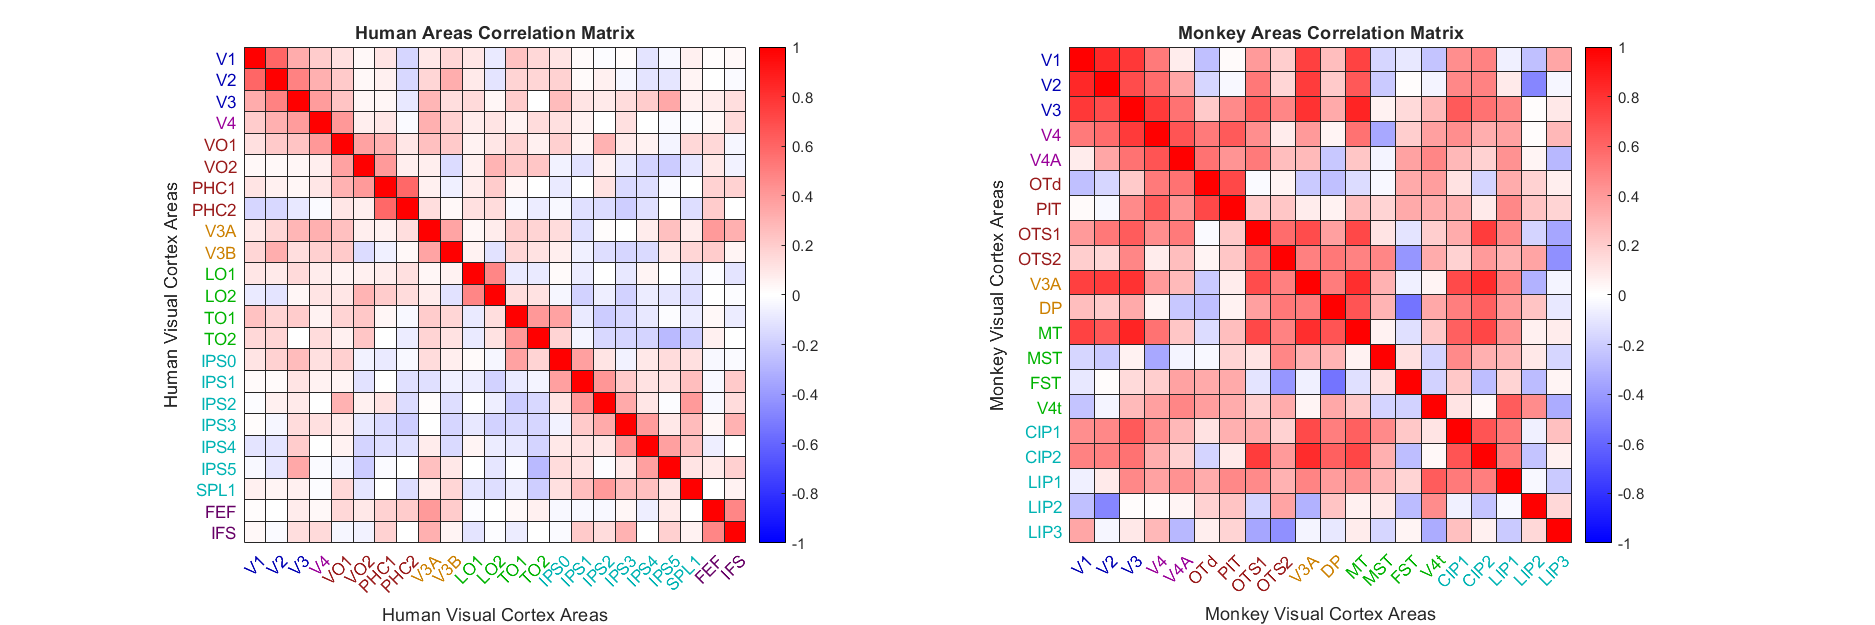

axp.Axes.XAxisLocation = 'top';
colormap(redblue);colorbar;caxis([-1 1]);
xlabel('Human Visual Cortex Areas')
ylabel('Human Visual Cortex Areas')
title('Human Areas Correlation Matrix')

subplot(1,2,2)
h2 = heatmap(alllabels_monkey_merge,alllabels_monkey_merge,all_area_corr_monkey);
Xticklabels = get(gca,'XDisplayLabels');
Xticklabels_new = cell(size(Xticklabels));
Yticklabels = get(gca,'YDisplayLabels');
Yticklabels_new = cell(size(Yticklabels));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], EVCcolor);
end
for i = 4:5
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], V4color);
end
for i = 6:9
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], ventralcolor);
end
for i = 10:11
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], dorsalcolor);
end
for i = 12:15
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], lateralcolor);
end
for i = 16:20
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Xticklabels{i}], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} ' Yticklabels{i}], parietalcolor);
end
h2.XDisplayLabels = Xticklabels_new;
h2.YDisplayLabels = Yticklabels_new;
colormap(redblue);colorbar;caxis([-1 1]);
xlabel('Monkey Visual Cortex Areas')
ylabel('Monkey Visual Cortex Areas')
title('Monkey Areas Correlation Matrix')

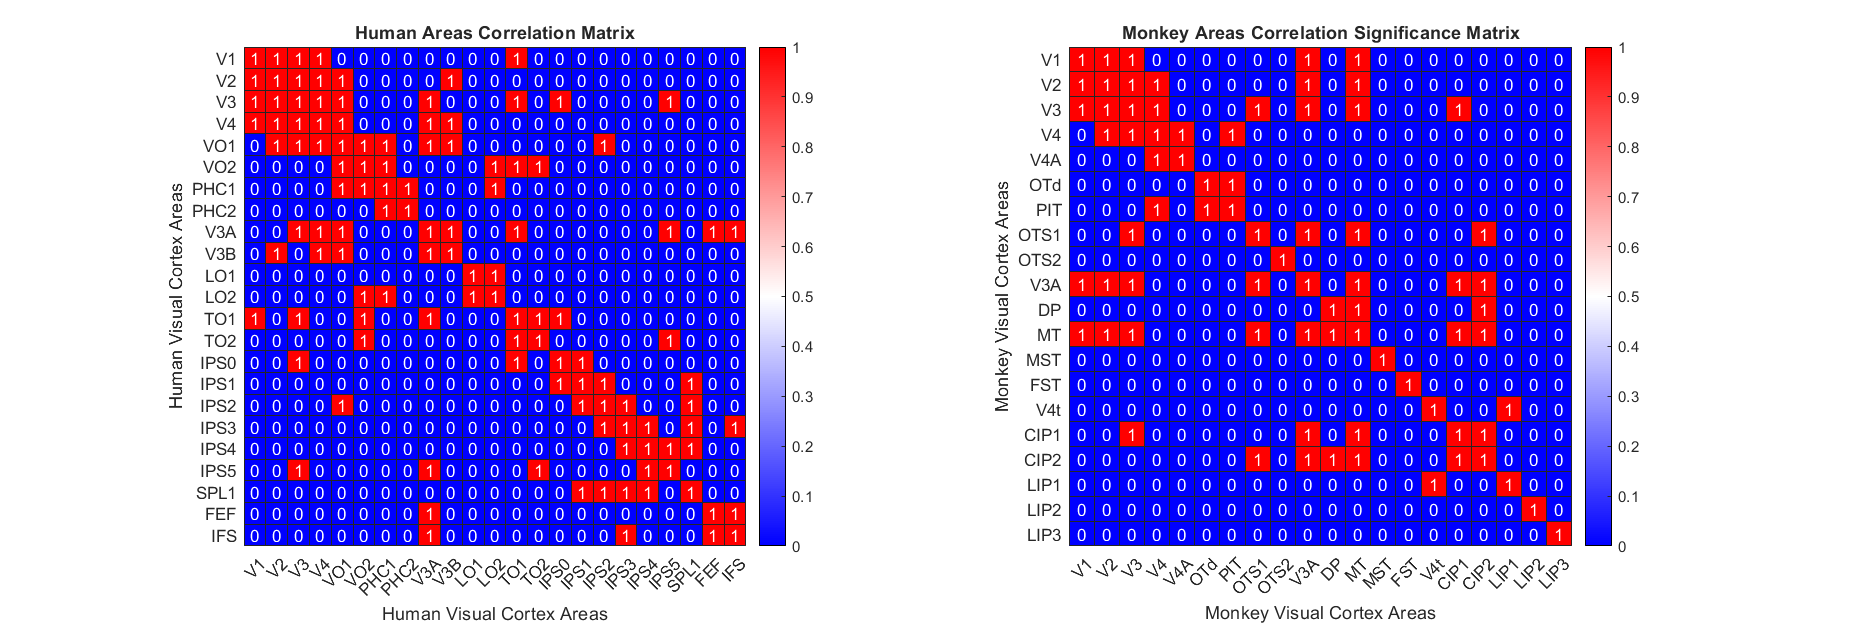


figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
subplot(1,2,1)
heatmap(alllabels_human_merge,alllabels_human_merge,double(all_area_pval_human<0.05));
colormap(redblue);colorbar;caxis([0 1]);
xlabel('Human Visual Cortex Areas')
ylabel('Human Visual Cortex Areas')
title('Human Areas Correlation Matrix')

subplot(1,2,2)
heatmap(alllabels_monkey_merge,alllabels_monkey_merge,double(all_area_pval_monkey<0.05));
colormap(redblue);colorbar;caxis([0 1]);
xlabel('Monkey Visual Cortex Areas')
ylabel('Monkey Visual Cortex Areas')
title('Monkey Areas Correlation Significance Matrix')

## Look at correlations of visual areas with V1 and TO1/MT

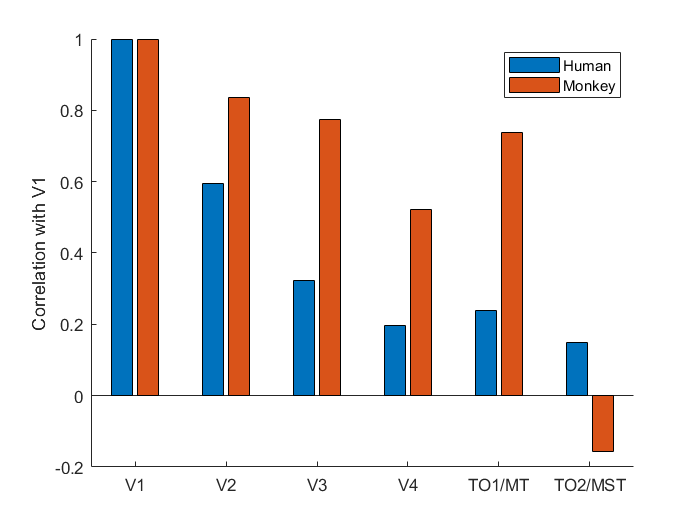

% should probably do some bootstrapping here
all_area_corr_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
all_area_pval_human = zeros(length(alllabels_human_merge),length(alllabels_human_merge));
for i = 1:length(alllabels_human_merge)
    for j = 1:length(alllabels_human_merge)
        include = ~isnan(surfacearea_human_merge(i,:)) & ~isnan(surfacearea_human_merge(j,:));
        [r,p] = corr(surfacearea_human_merge(i,include)',surfacearea_human_merge(j,include)');
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
all_area_pval_monkey = zeros(length(alllabels_monkey_merge),length(alllabels_monkey_merge));
for i = 1:length(alllabels_monkey_merge)
    for j = 1:length(alllabels_monkey_merge)
        include = ~isnan(surfacearea_monkey_merge(i,:)) & ~isnan(surfacearea_monkey_merge(j,:));
        [r,p] = corr(surfacearea_monkey_merge(i,include)',surfacearea_monkey_merge(j,include)');
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

xlab = {'V1','V2','V3','V4','TO1/MT','TO2/MST'};
all_area_corr = [all_area_corr_human([1:4,13,14],1), all_area_corr_monkey([1:4,12,13],1)];
h_color = [use_colorscale_human([1:4,7],:);use_colorscale_human(7,:)];
m_color = [use_colorscale_monkey([1:4,7],:);use_colorscale_monkey(7,:)];

figure;
b = bar(all_area_corr);
xticklabels(xlab)
ylabel('Correlation with V1')
legend('Human','Monkey')
box off

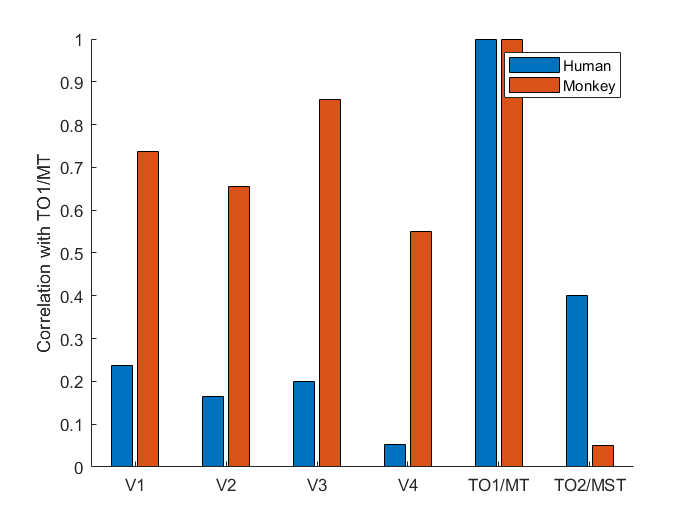

% b(1,:).CData = h_color;
% b(2,:).CData = m_color;

xlab = {'V1','V2','V3','V4','TO1/MT','TO2/MST'};
all_area_corr = [all_area_corr_human([1:4,13,14],13), all_area_corr_monkey([1:4,12,13],12)];

figure;
bar(all_area_corr)
xticklabels(xlab)
ylabel('Correlation with TO1/MT')
legend('Human','Monkey')
box off

## Look at relative size of V2/V1 and MT/V1 as in Rosa, 2002

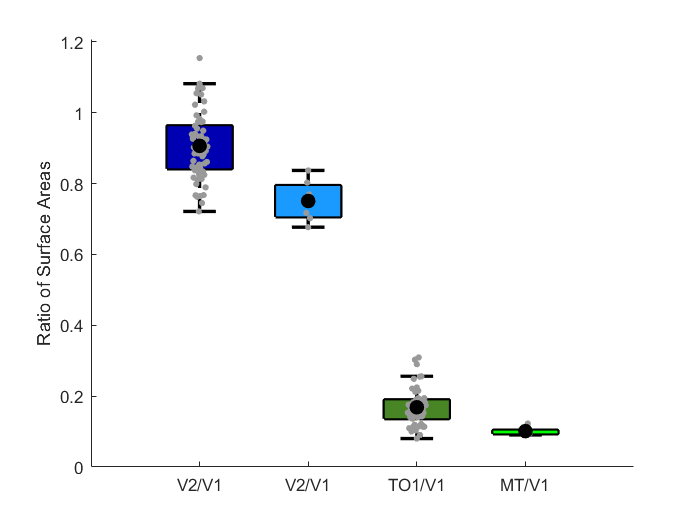

% paper says V2/V1 in humans = 1? just doesn't make sense
V2_to_hV1 = v_human(2,:)./v_human(1,:);
TO1_to_hV1 = v_human(14,:)./v_human(1,:);
vals_h = [V2_to_hV1; TO1_to_hV1]';
color_h = [7 1];

V2_to_mV1 = v_monkey(2,:)./v_monkey(1,:);
MT_to_mV1 = v_monkey(13,:)./v_monkey(1,:);
vals_m = [V2_to_mV1; MT_to_mV1]';
color_m = [7 1];

figure();
hold on
h1=boxplot(vals_h,'positions',[1,3],'notch','off','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j = 1:size(vals_h,2)
    patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_human(color_h(j),:),'FaceAlpha',1);
end
plotSpread(vals_h,'xValues',[1 3],'distributionColors',[.6 .6 .6],'spreadWidth',.2)
plot([1 3],nanmean(vals_h),'k.','MarkerSize',30);

h1=boxplot(vals_m,'positions',[2,4],'notch','off','colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j = 1:size(vals_m,2)
    patch(get(h1(j),'XData'),get(h1(j),'YData'),use_colorscale_monkey(color_m(j),:),'FaceAlpha',1);
end
plotSpread(vals_m,'xValues',[2,4],'distributionColors',[.6 .6 .6],'spreadWidth',.2)
plot([2,4],nanmean(vals_m),'k.','MarkerSize',30);
xticks(1:4)
xticklabels({'V2/V1','V2/V1','TO1/V1','MT/V1'})
ylabel('Ratio of Surface Areas')
box off

## Regression of Area Combinations - Humans

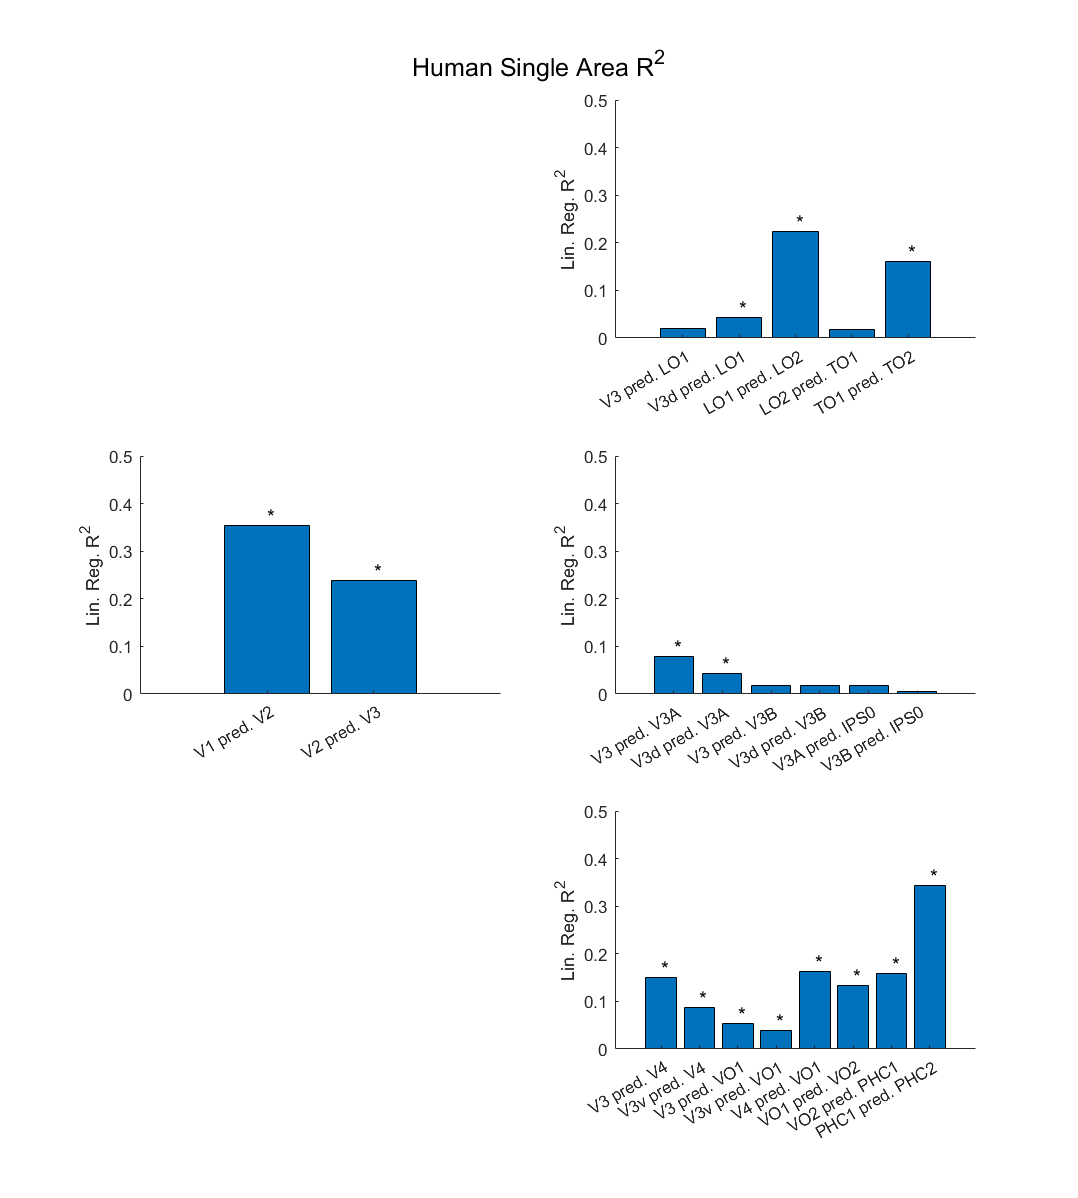

v1 = surfacearea_human_merge(1,:);
v2 = surfacearea_human_merge(2,:);
v3 = surfacearea_human_merge(3,:);
v3v = concat_bothhemi_human(5,:);
v3d = concat_bothhemi_human(6,:);
v4 = surfacearea_human_merge(4,:);
vo1 = surfacearea_human_merge(5,:);
vo2 = surfacearea_human_merge(6,:);
phc1 = surfacearea_human_merge(7,:);
phc2 = surfacearea_human_merge(8,:);
v3a = surfacearea_human_merge(9,:);
v3b = surfacearea_human_merge(10,:);
lo1 = surfacearea_human_merge(11,:);
lo2 = surfacearea_human_merge(12,:);
to1 = surfacearea_human_merge(13,:);
to2 = surfacearea_human_merge(14,:);
ips0 = surfacearea_human_merge(15,:);

% HUMAN INDIVIDUAL MODELS
% p values refer to F-statistic of linear fit vs constant model

% vc
human_v1_v2_mdl = fitlm(v1,v2);
human_v1_v2_R2 = human_v1_v2_mdl.Rsquared.Ordinary;
human_v1_v2_p = anova(human_v1_v2_mdl,'summary').pValue('Model');

human_v2_v3_mdl = fitlm(v2,v3);
human_v2_v3_R2 = human_v2_v3_mdl.Rsquared.Ordinary;
human_v2_v3_p = anova(human_v2_v3_mdl,'summary').pValue('Model');

% lat temp
human_v3_lo1_mdl = fitlm(v3,lo1);
human_v3_lo1_R2 = human_v3_lo1_mdl.Rsquared.Ordinary;
human_v3_lo1_p = anova(human_v3_lo1_mdl,'summary').pValue('Model');

human_v3d_lo1_mdl = fitlm(v3d,lo1);
human_v3d_lo1_R2 = human_v3d_lo1_mdl.Rsquared.Ordinary;
human_v3d_lo1_p = anova(human_v3d_lo1_mdl,'summary').pValue('Model');

human_lo1_lo2_mdl = fitlm(lo1,lo2);
human_lo1_lo2_R2 = human_lo1_lo2_mdl.Rsquared.Ordinary;
human_lo1_lo2_p = anova(human_lo1_lo2_mdl,'summary').pValue('Model');

human_lo2_to1_mdl = fitlm(lo2,to1);
human_lo2_to1_R2 = human_lo2_to1_mdl.Rsquared.Ordinary;
human_lo2_to1_p = anova(human_lo2_to1_mdl,'summary').pValue('Model');

human_to1_to2_mdl = fitlm(to1,to2);
human_to1_to2_R2 = human_to1_to2_mdl.Rsquared.Ordinary;
human_to1_to2_p = anova(human_to1_to2_mdl,'summary').pValue('Model');

% ips
human_v3_v3a_mdl = fitlm(v3,v3a);
human_v3_v3a_R2 = human_v3_v3a_mdl.Rsquared.Ordinary;
human_v3_v3a_p = anova(human_v3_v3a_mdl,'summary').pValue('Model');

human_v3d_v3a_mdl = fitlm(v3d,v3a);
human_v3d_v3a_R2 = human_v3d_v3a_mdl.Rsquared.Ordinary;
human_v3d_v3a_p = anova(human_v3d_v3a_mdl,'summary').pValue('Model');

human_v3_v3b_mdl = fitlm(v3,v3b);
human_v3_v3b_R2 = human_v3_v3b_mdl.Rsquared.Ordinary;
human_v3_v3b_p = anova(human_v3_v3b_mdl,'summary').pValue('Model');

human_v3d_v3b_mdl = fitlm(v3d,v3b);
human_v3d_v3b_R2 = human_v3d_v3b_mdl.Rsquared.Ordinary;
human_v3d_v3b_p = anova(human_v3d_v3b_mdl,'summary').pValue('Model');

human_v3a_ips0_mdl = fitlm(v3a,ips0);
human_v3a_ips0_R2 = human_v3a_ips0_mdl.Rsquared.Ordinary;
human_v3a_ips0_p = anova(human_v3a_ips0_mdl,'summary').pValue('Model');

human_v3b_ips0_mdl = fitlm(v3b,ips0);
human_v3b_ips0_R2 = human_v3b_ips0_mdl.Rsquared.Ordinary;
human_v3b_ips0_p = anova(human_v3b_ips0_mdl,'summary').pValue('Model');

% ventral
human_v3_v4_mdl = fitlm(v3,v4);
human_v3_v4_R2 = human_v3_v4_mdl.Rsquared.Ordinary;
human_v3_v4_p = anova(human_v3_v4_mdl,'summary').pValue('Model');

human_v3v_v4_mdl = fitlm(v3v,v4);
human_v3v_v4_R2 = human_v3v_v4_mdl.Rsquared.Ordinary;
human_v3v_v4_p = anova(human_v3v_v4_mdl,'summary').pValue('Model');

human_v3_vo1_mdl = fitlm(v3,vo1);
human_v3_vo1_R2 = human_v3_vo1_mdl.Rsquared.Ordinary;
human_v3_vo1_p = anova(human_v3_vo1_mdl,'summary').pValue('Model');

human_v3v_vo1_mdl = fitlm(v3v,vo1);
human_v3v_vo1_R2 = human_v3v_vo1_mdl.Rsquared.Ordinary;
human_v3v_vo1_p = anova(human_v3v_vo1_mdl,'summary').pValue('Model');

human_v4_vo1_mdl = fitlm(v4,vo1);
human_v4_vo1_R2 = human_v4_vo1_mdl.Rsquared.Ordinary;
human_v4_vo1_p = anova(human_v4_vo1_mdl,'summary').pValue('Model');

human_vo1_vo2_mdl = fitlm(vo1,vo2);
human_vo1_vo2_R2 = human_vo1_vo2_mdl.Rsquared.Ordinary;
human_vo1_vo2_p = anova(human_vo1_vo2_mdl,'summary').pValue('Model');

human_vo2_phc1_mdl = fitlm(vo2,phc1);
human_vo2_phc1_R2 = human_vo2_phc1_mdl.Rsquared.Ordinary;
human_vo2_phc1_p = anova(human_vo2_phc1_mdl,'summary').pValue('Model');

human_phc1_phc2_mdl = fitlm(phc1,phc2);
human_phc1_phc2_R2 = human_phc1_phc2_mdl.Rsquared.Ordinary;
human_phc1_phc2_p = anova(human_phc1_phc2_mdl,'summary').pValue('Model');

vc_R2_human = [human_v1_v2_R2;human_v2_v3_R2];
vc_p_human = [human_v1_v2_p;human_v2_v3_p];
lattemp_R2_human = [human_v3_lo1_R2;human_v3d_lo1_R2;human_lo1_lo2_R2;human_lo2_to1_R2;human_to1_to2_R2];
lattemp_p_human = [human_v3_lo1_p;human_v3d_lo1_p;human_lo1_lo2_p;human_lo2_to1_p;human_to1_to2_p];
ips_R2_human = [human_v3_v3a_R2;human_v3d_v3a_R2;human_v3_v3b_R2;human_v3d_v3b_R2;human_v3a_ips0_R2;human_v3b_ips0_R2];
ips_p_human = [human_v3_v3a_p;human_v3d_v3a_p;human_v3_v3b_p;human_v3d_v3b_p;human_v3a_ips0_p;human_v3b_ips0_p];
ventral_R2_human = [human_v3_v4_R2;human_v3v_v4_R2;human_v3_vo1_R2;human_v3v_vo1_R2;human_v4_vo1_R2;human_vo1_vo2_R2;human_vo2_phc1_R2;human_phc1_phc2_R2];
ventral_p_human = [human_v3_v4_p;human_v3v_v4_p;human_v3_vo1_p;human_v3v_vo1_p;human_v4_vo1_p;human_vo1_vo2_p;human_vo2_phc1_p;human_phc1_phc2_p];


f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
subplot(3,2,3)
bar(vc_R2_human)
for i = 1:length(vc_p_human)
    if vc_p_human(i)<0.05
        text(i,vc_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V1 pred. V2','V2 pred. V3'})
xtickangle(30)
ylabel('Lin. Reg. R^2')
ylim([0 0.5])
box off

subplot(3,2,2)
bar(lattemp_R2_human)
for i = 1:length(lattemp_p_human)
    if lattemp_p_human(i)<0.05
        text(i,lattemp_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V3 pred. LO1','V3d pred. LO1','LO1 pred. LO2','LO2 pred. TO1','TO1 pred. TO2'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
ylim([0 0.5])
box off

subplot(3,2,4)
bar(ips_R2_human)
for i = 1:length(ips_p_human)
    if ips_p_human(i)<0.05
        text(i,ips_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V3 pred. V3A','V3d pred. V3A','V3 pred. V3B','V3d pred. V3B','V3A pred. IPS0','V3B pred. IPS0'})
ylabel('Lin. Reg. R^2')
ylim([0 0.5])
xtickangle(30)
box off
sgtitle('Human Single Area R^2')

subplot(3,2,6)
bar(ventral_R2_human)
for i = 1:length(ventral_p_human)
    if ventral_p_human(i)<0.05
        text(i,ventral_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V3 pred. V4','V3v pred. V4','V3 pred. VO1','V3v pred. VO1','V4 pred. VO1','VO1 pred. VO2','VO2 pred. PHC1','PHC1 pred. PHC2'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
ylim([0 0.5])
box off
sgtitle('Human Single Area R^2')

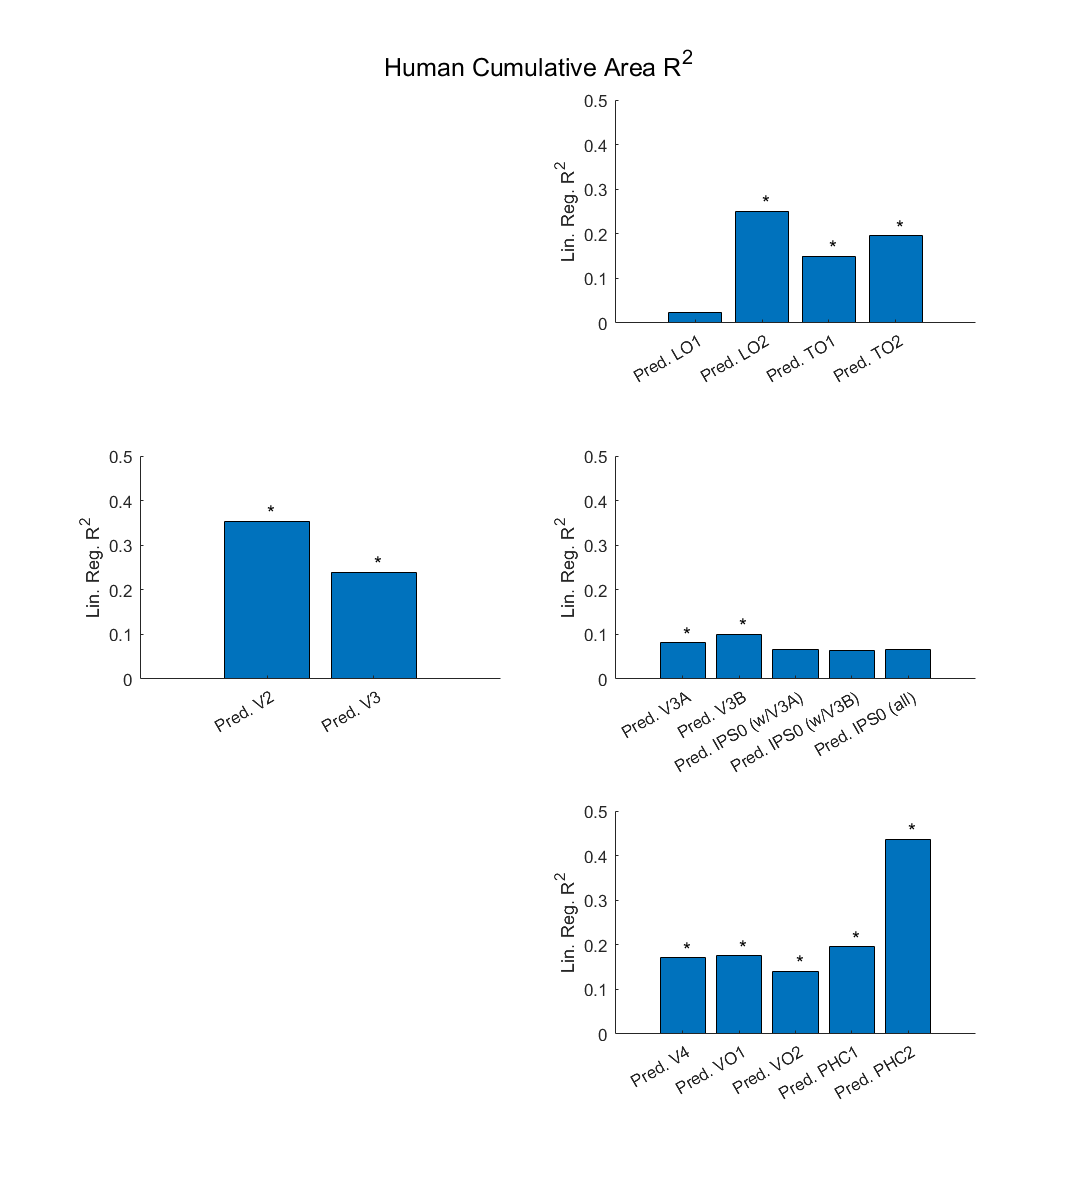


% HUMAN CUMULATIVE MODELS

v1v2 = [v1;v2]';
v1v2v3 = [v1;v2;v3]';
v1v2v3v4 = [v1;v2;v3;v4]';
v1v2v3v4vo1 = [v1;v2;v3;v4;vo1]';
v1v2v3v4vo1vo2 = [v1;v2;v3;v4;vo1;vo2]';
v1v2v3v4vo1vo2phc1 = [v1;v2;v3;v4;vo1;vo2;phc1]';
v1v2v3lo1 = [v1;v2;v3;lo1]';
v1v2v3lo1lo2 = [v1;v2;v3;lo1;lo2]';
v1v2v3lo1lo2to1 = [v1;v2;v3;lo1;lo2;to1]';
v1v2v3v3a = [v1;v2;v3;v3a]';
v1v2v3v3b = [v1;v2;v3;v3b]';
v1v2v3v3av3b = [v1;v2;v3;v3a;v3b]';
v1v2v3v3aips0 = [v1;v2;v3;v3a;ips0]';
v1v2v3v3bips0 = [v1;v2;v3;v3b;ips0]';

human_v1v2_v3_mdl = fitlm(v1v2,v3);
human_v1v2_v3_R2 = human_v1v2_v3_mdl.Rsquared.Ordinary;
human_v1v2_v3_p = anova(human_v1v2_v3_mdl,'summary').pValue('Model');

human_v1v2v3_lo1_mdl = fitlm(v1v2v3,lo1);
human_v1v2v3_lo1_R2 = human_v1v2v3_lo1_mdl.Rsquared.Ordinary;
human_v1v2v3_lo1_p = anova(human_v1v2v3_lo1_mdl,'summary').pValue('Model');

human_v1v2v3lo1_lo2_mdl = fitlm(v1v2v3lo1,lo2);
human_v1v2v3lo1_lo2_R2 = human_v1v2v3lo1_lo2_mdl.Rsquared.Ordinary;
human_v1v2v3lo1_lo2_p = anova(human_v1v2v3lo1_lo2_mdl,'summary').pValue('Model');

human_v1v2v3lo1lo2_to1_mdl = fitlm(v1v2v3lo1lo2,to1);
human_v1v2v3lo1lo2_to1_R2 = human_v1v2v3lo1lo2_to1_mdl.Rsquared.Ordinary;
human_v1v2v3lo1lo2_to1_p = anova(human_v1v2v3lo1lo2_to1_mdl,'summary').pValue('Model');

human_v1v2v3lo1lo2to1_to2_mdl = fitlm(v1v2v3lo1lo2to1,to2);
human_v1v2v3lo1lo2to1_to2_R2 = human_v1v2v3lo1lo2to1_to2_mdl.Rsquared.Ordinary;
human_v1v2v3lo1lo2to1_to2_p = anova(human_v1v2v3lo1lo2to1_to2_mdl,'summary').pValue('Model');

human_v1v2v3_v3a_mdl = fitlm(v1v2v3,v3a);
human_v1v2v3_v3a_R2 = human_v1v2v3_v3a_mdl.Rsquared.Ordinary;
human_v1v2v3_v3a_p = anova(human_v1v2v3_v3a_mdl,'summary').pValue('Model');

human_v1v2v3_v3b_mdl = fitlm(v1v2v3,v3b);
human_v1v2v3_v3b_R2 = human_v1v2v3_v3b_mdl.Rsquared.Ordinary;
human_v1v2v3_v3b_p = anova(human_v1v2v3_v3b_mdl,'summary').pValue('Model');

human_v1v2v3v3a_ips0_mdl = fitlm(v1v2v3v3a,ips0);
human_v1v2v3v3a_ips0_R2 = human_v1v2v3v3a_ips0_mdl.Rsquared.Ordinary;
human_v1v2v3v3a_ips0_p = anova(human_v1v2v3v3a_ips0_mdl,'summary').pValue('Model');

human_v1v2v3v3b_ips0_mdl = fitlm(v1v2v3v3b,ips0);
human_v1v2v3v3b_ips0_R2 = human_v1v2v3v3b_ips0_mdl.Rsquared.Ordinary;
human_v1v2v3v3b_ips0_p = anova(human_v1v2v3v3b_ips0_mdl,'summary').pValue('Model');

human_v1v2v3v3av3b_ips0_mdl = fitlm(v1v2v3v3av3b,ips0);
human_v1v2v3v3av3b_ips0_R2 = human_v1v2v3v3av3b_ips0_mdl.Rsquared.Ordinary;
human_v1v2v3v3av3b_ips0_p = anova(human_v1v2v3v3av3b_ips0_mdl,'summary').pValue('Model');

human_v1v2v3_v4_mdl = fitlm(v1v2v3,v4);
human_v1v2v3_v4_R2 = human_v1v2v3_v4_mdl.Rsquared.Ordinary;
human_v1v2v3_v4_p = anova(human_v1v2v3_v4_mdl,'summary').pValue('Model');

human_v1v2v3v4_vo1_mdl = fitlm(v1v2v3v4,vo1);
human_v1v2v3v4_vo1_R2 = human_v1v2v3v4_vo1_mdl.Rsquared.Ordinary;
human_v1v2v3v4_vo1_p = anova(human_v1v2v3v4_vo1_mdl,'summary').pValue('Model');

human_v1v2v3v4vo1_vo2_mdl = fitlm(v1v2v3v4vo1,vo2);
human_v1v2v3v4vo1_vo2_R2 = human_v1v2v3v4vo1_vo2_mdl.Rsquared.Ordinary;
human_v1v2v3v4vo1_vo2_p = anova(human_v1v2v3v4vo1_vo2_mdl,'summary').pValue('Model');

human_v1v2v3v4vo1vo2_phc1_mdl = fitlm(v1v2v3v4vo1vo2,phc1);
human_v1v2v3v4vo1vo2_phc1_R2 = human_v1v2v3v4vo1vo2_phc1_mdl.Rsquared.Ordinary;
human_v1v2v3v4vo1vo2_phc1_p = anova(human_v1v2v3v4vo1vo2_phc1_mdl,'summary').pValue('Model');

human_v1v2v3v4vo1vo2phc1_phc2_mdl = fitlm(v1v2v3v4vo1vo2phc1,phc2);
human_v1v2v3v4vo1vo2phc1_phc2_R2 = human_v1v2v3v4vo1vo2phc1_phc2_mdl.Rsquared.Ordinary;
human_v1v2v3v4vo1vo2phc1_phc2_p = anova(human_v1v2v3v4vo1vo2phc1_phc2_mdl,'summary').pValue('Model');

vc_cumul_R2_human = [human_v1_v2_R2;human_v1v2_v3_R2];
vc_cumul_p_human = [human_v1_v2_p;human_v1v2_v3_p];
lattemp_cumul_R2_human = [human_v1v2v3_lo1_R2;human_v1v2v3lo1_lo2_R2;human_v1v2v3lo1lo2_to1_R2;human_v1v2v3lo1lo2to1_to2_R2];
lattemp_cumul_p_human = [human_v1v2v3_lo1_p;human_v1v2v3lo1_lo2_p;human_v1v2v3lo1lo2_to1_p;human_v1v2v3lo1lo2to1_to2_p];
ips_cumul_R2_human = [human_v1v2v3_v3a_R2;human_v1v2v3_v3b_R2;human_v1v2v3v3a_ips0_R2;human_v1v2v3v3b_ips0_R2;human_v1v2v3v3av3b_ips0_R2];
ips_cumul_p_human = [human_v1v2v3_v3a_p;human_v1v2v3_v3b_p;human_v1v2v3v3a_ips0_p;human_v1v2v3v3b_ips0_p;human_v1v2v3v3av3b_ips0_p];
ventral_cumul_R2_human = [human_v1v2v3_v4_R2;human_v1v2v3v4_vo1_R2;human_v1v2v3v4vo1_vo2_R2;human_v1v2v3v4vo1vo2_phc1_R2;human_v1v2v3v4vo1vo2phc1_phc2_R2];
ventral_cumul_p_human = [human_v1v2v3_v4_p;human_v1v2v3v4_vo1_p;human_v1v2v3v4vo1_vo2_p;human_v1v2v3v4vo1vo2_phc1_p;human_v1v2v3v4vo1vo2phc1_phc2_p];

f = figure('Renderer', 'painters', 'Position', [10 10 900 1000]);
subplot(3,2,3)
bar(vc_cumul_R2_human)
for i = 1:length(vc_cumul_p_human)
    if vc_cumul_p_human(i)<0.05
        text(i,vc_cumul_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'Pred. V2','Pred. V3'})
xtickangle(30)
ylim([0 0.5])
ylabel('Lin. Reg. R^2')
box off

subplot(3,2,2)
bar(lattemp_cumul_R2_human)
for i = 1:length(lattemp_cumul_p_human)
    if lattemp_cumul_p_human(i)<0.05
        text(i,lattemp_cumul_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'Pred. LO1','Pred. LO2','Pred. TO1','Pred. TO2'})
ylabel('Lin. Reg. R^2')
ylim([0 0.5])
xtickangle(30)
box off

subplot(3,2,4)
bar(ips_cumul_R2_human)
for i = 1:length(ips_cumul_p_human)
    if ips_cumul_p_human(i)<0.05
        text(i,ips_cumul_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'Pred. V3A','Pred. V3B','Pred. IPS0 (w/V3A)','Pred. IPS0 (w/V3B)','Pred. IPS0 (all)'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
ylim([0 0.5])
box off

subplot(3,2,6)
bar(ventral_cumul_R2_human)
for i = 1:length(ventral_cumul_p_human)
    if ventral_cumul_p_human(i)<0.05
        text(i,ventral_cumul_R2_human(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'Pred. V4','Pred. VO1','Pred. VO2','Pred. PHC1','Pred. PHC2'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
ylim([0 0.5])
box off
sgtitle('Human Cumulative Area R^2')

## Regression of Area Combinations - Monkeys

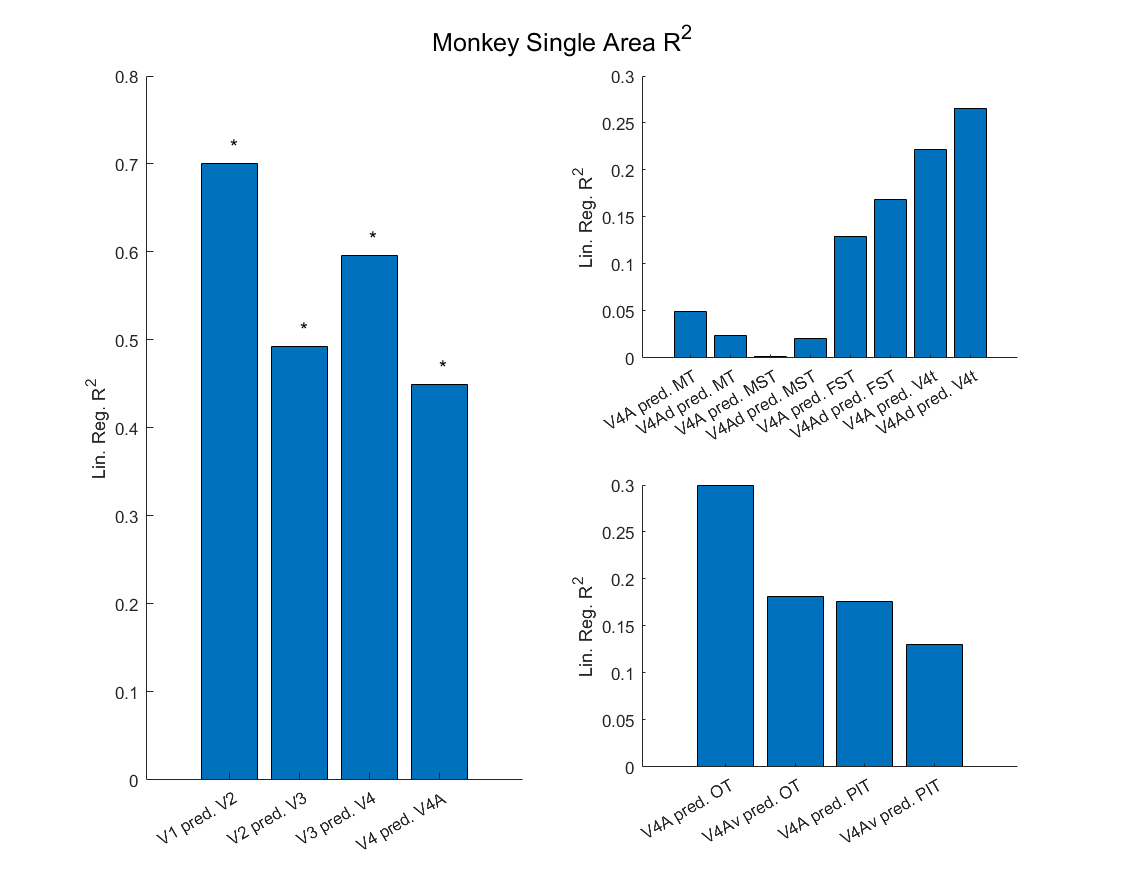

% MONKEY SINGLE AREA MODELS

v1 = surfacearea_monkey_merge(1,:);
v2 = surfacearea_monkey_merge(2,:);
v3 = surfacearea_monkey_merge(3,:);
v4 = surfacearea_monkey_merge(4,:);
v4a = surfacearea_monkey_merge(5,:);
v4av = concat_bothhemi_monkey(9,:);
v4ad = concat_bothhemi_monkey(10,:);
mt = surfacearea_monkey_merge(12,:);
mst = surfacearea_monkey_merge(13,:);
fst = surfacearea_monkey_merge(14,:);
v4t = surfacearea_monkey_merge(15,:);
ot = surfacearea_monkey_merge(6,:);
pit = surfacearea_monkey_merge(7,:);

v1v2 = [v1;v2]';
v1v2v3 = [v1;v2;v3]';
v1v2v3v4 = [v1;v2;v3;v4]';
v1v2v3v4v4a = [v1;v2;v3;v4;v4a]';

monkey_v1_v2_mdl = fitlm(v1,v2);
monkey_v1_v2_R2 = monkey_v1_v2_mdl.Rsquared.Ordinary;
monkey_v1_v2_p = anova(monkey_v1_v2_mdl,'summary').pValue('Model');

monkey_v2_v3_mdl = fitlm(v2,v3);
monkey_v2_v3_R2 = monkey_v2_v3_mdl.Rsquared.Ordinary;
monkey_v2_v3_p = anova(monkey_v2_v3_mdl,'summary').pValue('Model');

monkey_v3_v4_mdl = fitlm(v3,v4);
monkey_v3_v4_R2 = monkey_v3_v4_mdl.Rsquared.Ordinary;
monkey_v3_v4_p = anova(monkey_v3_v4_mdl,'summary').pValue('Model');

monkey_v4_v4a_mdl = fitlm(v4,v4a);
monkey_v4_v4a_R2 = monkey_v4_v4a_mdl.Rsquared.Ordinary;
monkey_v4_v4a_p = anova(monkey_v4_v4a_mdl,'summary').pValue('Model');

monkey_v4a_mt_mdl = fitlm(v4a,mt);
monkey_v4a_mt_R2 = monkey_v4a_mt_mdl.Rsquared.Ordinary;
monkey_v4a_mt_p = anova(monkey_v4a_mt_mdl,'summary').pValue('Model');

monkey_v4ad_mt_mdl = fitlm(v4ad,mt);
monkey_v4ad_mt_R2 = monkey_v4ad_mt_mdl.Rsquared.Ordinary;
monkey_v4ad_mt_p = anova(monkey_v4ad_mt_mdl,'summary').pValue('Model');

monkey_v4a_mst_mdl = fitlm(v4a,mst);
monkey_v4a_mst_R2 = monkey_v4a_mst_mdl.Rsquared.Ordinary;
monkey_v4a_mst_p = anova(monkey_v4a_mst_mdl,'summary').pValue('Model');

monkey_v4ad_mst_mdl = fitlm(v4ad,mst);
monkey_v4ad_mst_R2 = monkey_v4ad_mst_mdl.Rsquared.Ordinary;
monkey_v4ad_mst_p = anova(monkey_v4ad_mst_mdl,'summary').pValue('Model');

monkey_v4a_fst_mdl = fitlm(v4a,fst);
monkey_v4a_fst_R2 = monkey_v4a_fst_mdl.Rsquared.Ordinary;
monkey_v4a_fst_p = anova(monkey_v4a_fst_mdl,'summary').pValue('Model');

monkey_v4ad_fst_mdl = fitlm(v4ad,fst);
monkey_v4ad_fst_R2 = monkey_v4ad_fst_mdl.Rsquared.Ordinary;
monkey_v4ad_fst_p = anova(monkey_v4ad_fst_mdl,'summary').pValue('Model');

monkey_v4a_v4t_mdl = fitlm(v4a,v4t);
monkey_v4a_v4t_R2 = monkey_v4a_v4t_mdl.Rsquared.Ordinary;
monkey_v4a_v4t_p = anova(monkey_v4a_v4t_mdl,'summary').pValue('Model');

monkey_v4ad_v4t_mdl = fitlm(v4ad,v4t);
monkey_v4ad_v4t_R2 = monkey_v4ad_v4t_mdl.Rsquared.Ordinary;
monkey_v4ad_v4t_p = anova(monkey_v4ad_v4t_mdl,'summary').pValue('Model');

monkey_v4a_ot_mdl = fitlm(v4a,ot);
monkey_v4a_ot_R2 = monkey_v4a_ot_mdl.Rsquared.Ordinary;
monkey_v4a_ot_p = anova(monkey_v4a_ot_mdl,'summary').pValue('Model');

monkey_v4av_ot_mdl = fitlm(v4av,ot);
monkey_v4av_ot_R2 = monkey_v4av_ot_mdl.Rsquared.Ordinary;
monkey_v4av_ot_p = anova(monkey_v4av_ot_mdl,'summary').pValue('Model');

monkey_v4a_pit_mdl = fitlm(v4a,pit);
monkey_v4a_pit_R2 = monkey_v4a_pit_mdl.Rsquared.Ordinary;
monkey_v4a_pit_p = anova(monkey_v4a_pit_mdl,'summary').pValue('Model');

monkey_v4av_pit_mdl = fitlm(v4av,pit);
monkey_v4av_pit_R2 = monkey_v4av_pit_mdl.Rsquared.Ordinary;
monkey_v4av_pit_p = anova(monkey_v4av_pit_mdl,'summary').pValue('Model');


vc_R2_monkey = [monkey_v1_v2_R2;monkey_v2_v3_R2;monkey_v3_v4_R2;monkey_v4_v4a_R2];
vc_p_monkey = [monkey_v1_v2_p;monkey_v2_v3_p;monkey_v3_v4_p;monkey_v4_v4a_p];
dorsal_R2_monkey = [monkey_v4a_mt_R2;monkey_v4ad_mt_R2;monkey_v4a_mst_R2;monkey_v4ad_mst_R2;monkey_v4a_fst_R2;monkey_v4ad_fst_R2;monkey_v4a_v4t_R2;monkey_v4ad_v4t_R2];
dorsal_p_monkey = [monkey_v4a_mt_p;monkey_v4ad_mt_p;monkey_v4a_mst_p;monkey_v4ad_mst_p;monkey_v4a_fst_p;monkey_v4ad_fst_p;monkey_v4a_v4t_p;monkey_v4ad_v4t_p];
ventral_R2_monkey = [monkey_v4a_ot_R2;monkey_v4av_ot_R2;monkey_v4a_pit_R2;monkey_v4av_pit_R2];
ventral_p_monkey = [monkey_v4a_ot_p;monkey_v4av_ot_p;monkey_v4a_pit_p;monkey_v4av_pit_p];


figure('Renderer', 'painters', 'Position', [10 10 900 700]);
subplot(2,2,[1 3])
bar(vc_R2_monkey)
for i = 1:length(vc_p_monkey)
    if vc_p_monkey(i)<0.05
        text(i,vc_R2_monkey(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V1 pred. V2','V2 pred. V3','V3 pred. V4','V4 pred. V4A'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
box off

subplot(2,2,2)
bar(dorsal_R2_monkey)
for i = 1:length(dorsal_p_monkey)
    if dorsal_p_monkey(i)<0.05
        text(i,dorsal_R2_monkey(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V4A pred. MT','V4Ad pred. MT','V4A pred. MST','V4Ad pred. MST','V4A pred. FST','V4Ad pred. FST','V4A pred. V4t','V4Ad pred. V4t'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
box off

subplot(2,2,4)
bar(ventral_R2_monkey)
for i = 1:length(ventral_p_monkey)
    if ventral_p_monkey(i)<0.05
        text(i,ventral_R2_monkey(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'V4A pred. OT','V4Av pred. OT','V4A pred. PIT','V4Av pred. PIT'})
ylabel('Lin. Reg. R^2')
xtickangle(30)
box off

sgtitle('Monkey Single Area R^2')

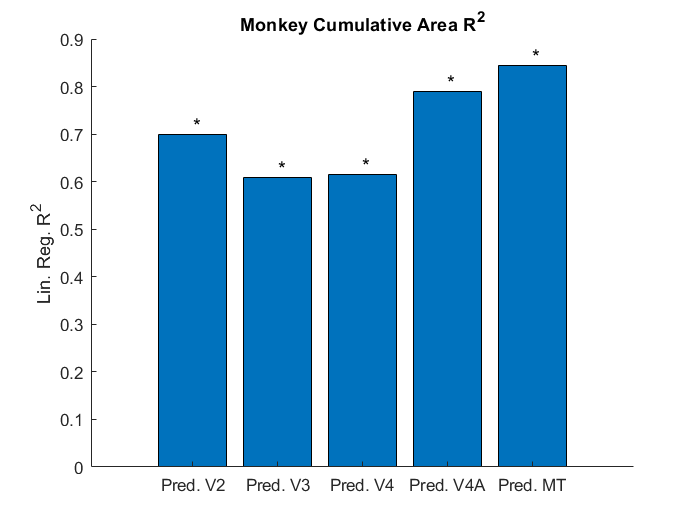


% MONKEY CUMULATIVE MODELS

monkey_v1v2_v3_mdl = fitlm(v1v2,v3);
monkey_v1v2_v3_R2 = monkey_v1v2_v3_mdl.Rsquared.Ordinary;
monkey_v1v2_v3_p = anova(monkey_v1v2_v3_mdl,'summary').pValue('Model');

monkey_v1v2v3_v4_mdl = fitlm(v1v2v3,v4);
monkey_v1v2v3_v4_R2 = monkey_v1v2v3_v4_mdl.Rsquared.Ordinary;
monkey_v1v2v3_v4_p = anova(monkey_v1v2v3_v4_mdl,'summary').pValue('Model');

monkey_v1v2v3v4_v4a_mdl = fitlm(v1v2v3v4,v4a);
monkey_v1v2v3v4_v4a_R2 = monkey_v1v2v3v4_v4a_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4_v4a_p = anova(monkey_v1v2v3v4_v4a_mdl,'summary').pValue('Model');

monkey_v1v2v3v4v4a_mt_mdl = fitlm(v1v2v3v4v4a,mt);
monkey_v1v2v3v4v4a_mt_R2 = monkey_v1v2v3v4v4a_mt_mdl.Rsquared.Ordinary;
monkey_v1v2v3v4v4a_mt_p = anova(monkey_v1v2v3v4v4a_mt_mdl,'summary').pValue('Model');

vc_cumu_R2_monkey = [monkey_v1_v2_R2;monkey_v1v2_v3_R2;monkey_v1v2v3_v4_R2;monkey_v1v2v3v4_v4a_R2;monkey_v1v2v3v4v4a_mt_R2];
vc_cumu_p_monkey = [monkey_v1_v2_p;monkey_v1v2_v3_p;monkey_v1v2v3_v4_p;monkey_v1v2v3v4_v4a_p;monkey_v1v2v3v4v4a_mt_p];


figure();
bar(vc_cumu_R2_monkey)
for i = 1:length(vc_cumu_p_monkey)
    if vc_cumu_p_monkey(i)<0.05
        text(i,vc_cumu_R2_monkey(i)+0.02,'*','FontSize',12)
    end
end
xticklabels({'Pred. V2','Pred. V3','Pred. V4','Pred. V4A','Pred. MT'})
ylabel('Lin. Reg. R^2')
box off
title('Monkey Cumulative Area R^2')

## Additional plots related to higher-order monkey areas

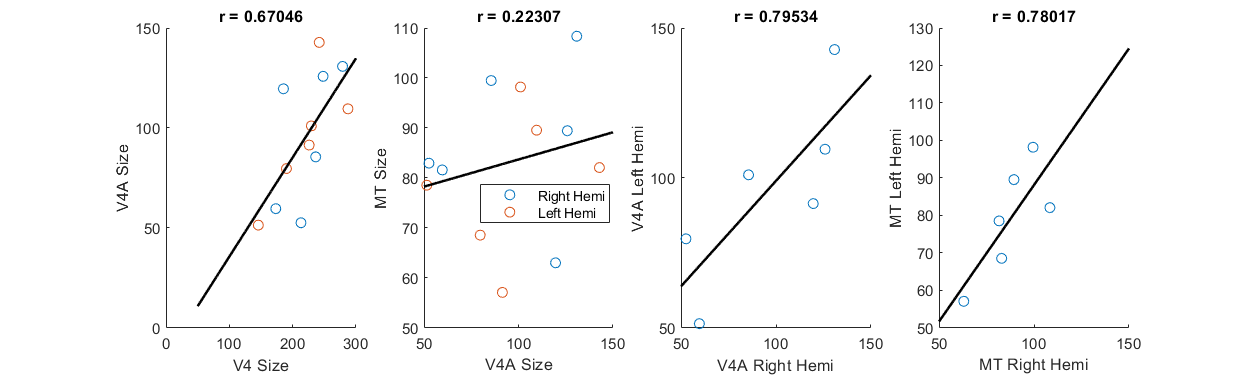

figure('Renderer', 'painters', 'Position', [10 10 1000 300]);
subplot(1,4,1)
scatter(v4(1:7),v4a(1:7))
hold on;
scatter(v4(8:end),v4a(8:end))
idx = ~isnan(v4) & ~isnan(v4a);
coefficients = polyfit(v4(idx),v4a(idx), 1);
xFit = linspace(50, 300, 1000);
yFit = polyval(coefficients , xFit);
plot(xFit,yFit,'k','linewidth',1.5)
title(['r = ', num2str(corr2(v4(idx),v4a(idx)))])
xlabel('V4 Size')
ylabel('V4A Size')

subplot(1,4,2)
scatter(v4a(1:7),mt(1:7))
hold on;
scatter(v4a(8:end),mt(8:end))
idx = ~isnan(v4a) & ~isnan(mt);
coefficients = polyfit(v4a(idx),mt(idx), 1);
xFit = linspace(50, 150, 1000);
yFit = polyval(coefficients , xFit);
plot(xFit,yFit,'k','linewidth',1.5)
title(['r = ', num2str(corr2(v4a(idx),mt(idx)))])
xlabel('V4A Size')
ylabel('MT Size')
legend('Right Hemi','Left Hemi','Location','best')

subplot(1,4,3)
v4a_new = v4a(~isnan(v4a));
scatter(v4a_new(1:6),v4a_new(7:end))
hold on;
coefficients = polyfit(v4a_new(1:6),v4a_new(7:end), 1);
xFit = linspace(50, 150, 1000);
yFit = polyval(coefficients , xFit);
plot(xFit,yFit,'k','linewidth',1.5)
title(['r = ', num2str(corr2(v4a_new(1:6),v4a_new(7:end)))])
xlabel('V4A Right Hemi')
ylabel('V4A Left Hemi')

subplot(1,4,4)
mt_new = mt(~isnan(mt));
scatter(mt_new(1:6),mt_new(7:end))
hold on;
coefficients = polyfit(mt_new(1:6),mt_new(7:end), 1);
xFit = linspace(50, 150, 1000);
yFit = polyval(coefficients , xFit);
plot(xFit,yFit,'k','linewidth',1.5)
title(['r = ', num2str(corr2(mt_new(1:6),mt_new(7:end)))])
xlabel('MT Right Hemi')
ylabel('MT Left Hemi')

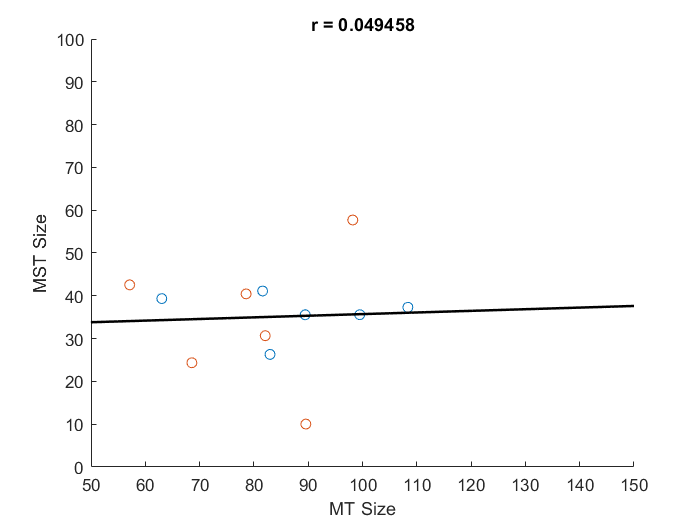

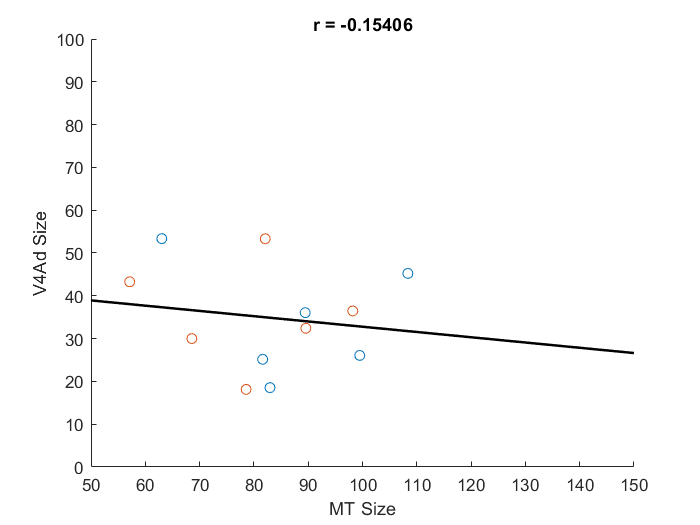

figure();
scatter(mt(1:7),mst(1:7))
hold on
scatter(mt(8:end),mst(8:end))
idx = ~isnan(mt) & ~isnan(mst);
coefficients = polyfit(mt(idx),mst(idx), 1);
xFit = linspace(0, 150, 1000);
yFit = polyval(coefficients , xFit);
plot(xFit,yFit,'k','linewidth',1.5)
title(['r = ', num2str(corr2(mt(idx),mst(idx)))])
xlim([50 150])
ylim([0 100])
xlabel('MT Size')
ylabel('MST Size')

## Supplementary Fig: Plot Cross-hemisphere Correlations

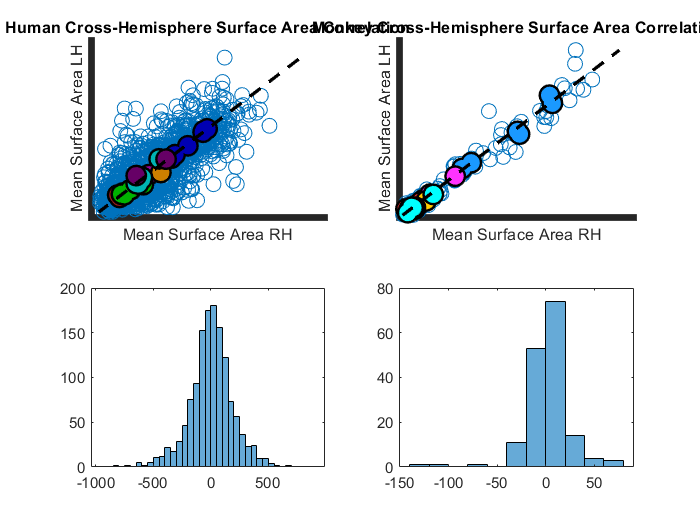

figure()
subplot(2,2,1)
scatter(surfacearea_human{1}(:),surfacearea_human{2}(:),80);
hold on
for rr = 1:length(allrois_human)
    plot(nanmean(surfacearea_human{1}(allrois_human{rr},:),2),nanmean(surfacearea_human{2}(allrois_human{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_human{1}(allrois_human{rr},:),2),nanmean(surfacearea_human{2}(allrois_human{rr},:),2),'.','Color',use_colorscale_unique_human(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_human{1}(:)),max(surfacearea_human{2}(:))]);
min_value=floor([min(surfacearea_human{1}(:)),min(surfacearea_human{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])
title('Human Cross-Hemisphere Surface Area Correlation')


subplot(2,2,2)
scatter(surfacearea_monkey{1}(:),surfacearea_monkey{2}(:),80);
hold on
for rr = 1:length(allrois_monkey)
    plot(nanmean(surfacearea_monkey{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(allrois_monkey{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_monkey{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey{2}(allrois_monkey{rr},:),2),'.','Color',use_colorscale_unique_monkey(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_monkey{1}(:)),max(surfacearea_monkey{2}(:))]);
min_value=floor([min(surfacearea_monkey{1}(:)),min(surfacearea_monkey{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');

title('Monkey Cross-Hemisphere Surface Area Correlation')
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])

subplot(2,2,3)
histogram(surfacearea_human{1}(:)-surfacearea_human{2}(:));

subplot(2,2,4)
histogram(surfacearea_monkey{1}(:)-surfacearea_monkey{2}(:));

[h,p] = vartest2(surfacearea_human{1}(:)-surfacearea_human{2}(:), surfacearea_monkey{1}(:)-surfacearea_monkey{2}(:));
disp([h, p])

    1.0000    0.0000



## Supplementary Fig: Plot Cross-hemisphere Correlations - Normalized

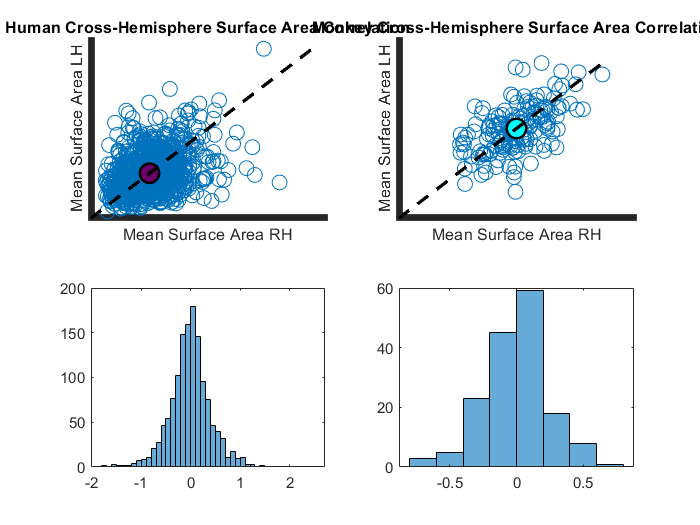

surfacearea_human_norm{1} = surfacearea_human{1} ./ mean(surfacearea_human{1},2,'omitnan');
surfacearea_human_norm{2} = surfacearea_human{2} ./ mean(surfacearea_human{2},2,'omitnan');

surfacearea_monkey_norm{1} = surfacearea_monkey{1} ./ mean(surfacearea_monkey{1},2,'omitnan');
surfacearea_monkey_norm{2} = surfacearea_monkey{2} ./ mean(surfacearea_monkey{2},2,'omitnan');

figure()
subplot(2,2,1)
scatter(surfacearea_human_norm{1}(:),surfacearea_human_norm{2}(:),80);
hold on
for rr = 1:length(allrois_human)
    plot(nanmean(surfacearea_human_norm{1}(allrois_human{rr},:),2),nanmean(surfacearea_human_norm{2}(allrois_human{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_human_norm{1}(allrois_human{rr},:),2),nanmean(surfacearea_human_norm{2}(allrois_human{rr},:),2),'.','Color',use_colorscale_unique_human(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_human_norm{1}(:)),max(surfacearea_human_norm{2}(:))]);
min_value=floor([min(surfacearea_human_norm{1}(:)),min(surfacearea_human_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])
title('Human Cross-Hemisphere Surface Area Correlation')


subplot(2,2,2)
scatter(surfacearea_monkey_norm{1}(:),surfacearea_monkey_norm{2}(:),80);
hold on
for rr = 1:length(allrois_monkey)
    plot(nanmean(surfacearea_monkey_norm{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey_norm{2}(allrois_monkey{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(surfacearea_monkey_norm{1}(allrois_monkey{rr},:),2),nanmean(surfacearea_monkey_norm{2}(allrois_monkey{rr},:),2),'.','Color',use_colorscale_unique_monkey(rr,:),'MarkerSize',35);
end
max_value=max([max(surfacearea_monkey_norm{1}(:)),max(surfacearea_monkey_norm{2}(:))]);
min_value=floor([min(surfacearea_monkey_norm{1}(:)),min(surfacearea_monkey_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');

title('Monkey Cross-Hemisphere Surface Area Correlation')
set(gca,'linewidth',4)
set(gca,'XTick',[])
set(gca,'YTick',[])

subplot(2,2,3)
histogram(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:));

subplot(2,2,4)
histogram(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:));

humanvar = var(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
humanstd = std(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
monkvar = var(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');
monkstd = std(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');

data1 = surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:);
data2 = surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:);
include = ~isnan(data1);data1 = data1(include);
include = ~isnan(data2);data2 = data2(include);
[h,p] = vartest2(data1, data2);
disp([h, p])

    1.0000    0.0000



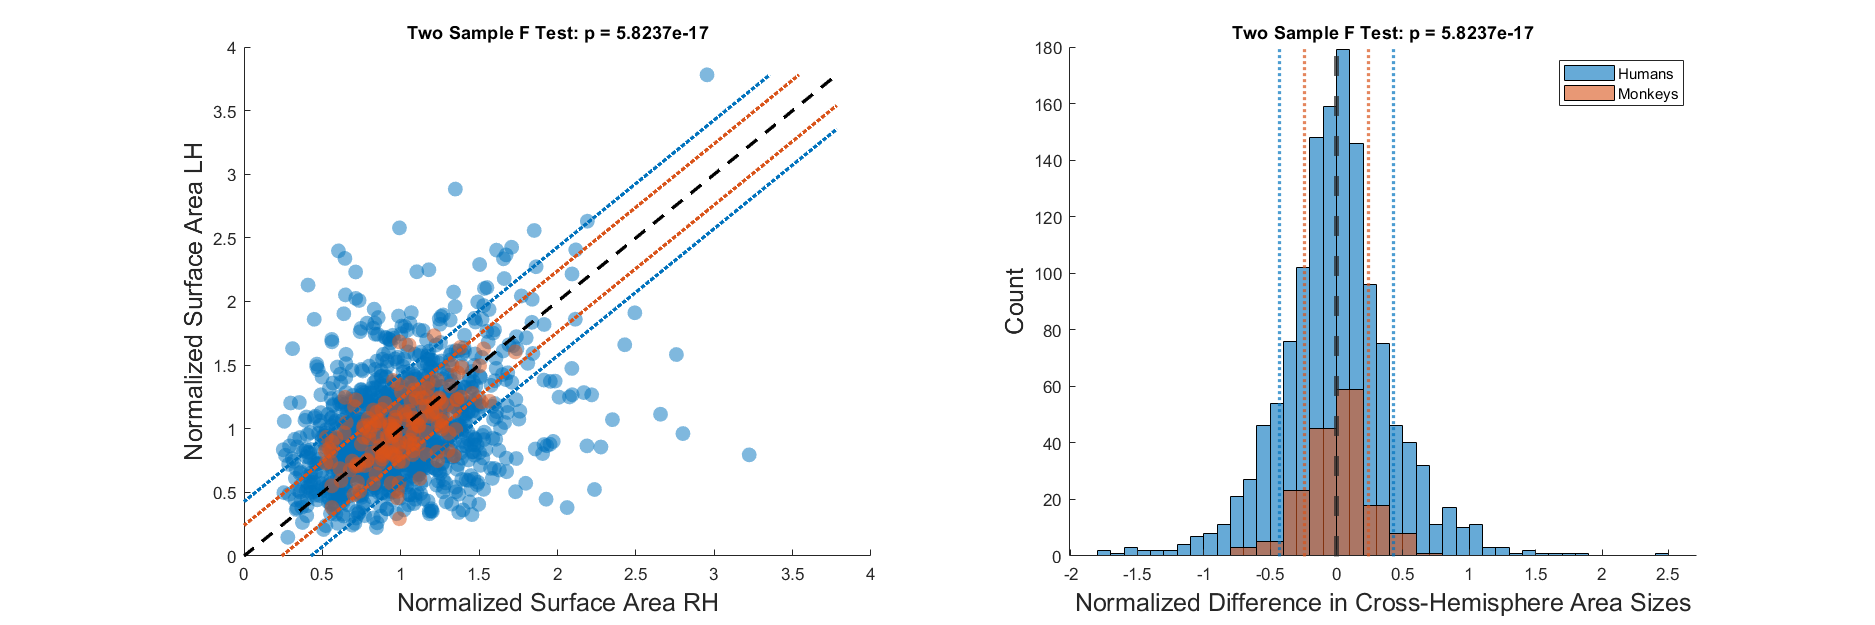


figure('Renderer', 'painters', 'Position', [10 10 1500 500])
subplot(1,2,1)
s1 = scatter(surfacearea_human_norm{1}(:),surfacearea_human_norm{2}(:),80,'filled');
s1.MarkerFaceAlpha = 0.5;
hold on;
s2 = scatter(surfacearea_monkey_norm{1}(:),surfacearea_monkey_norm{2}(:),80,'filled');
s2.MarkerFaceAlpha = 0.5;
max_value=max([max(surfacearea_human_norm{1}(:)),max(surfacearea_human_norm{2}(:))]);
min_value=floor([min(surfacearea_human_norm{1}(:)),min(surfacearea_human_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
plot([min_value, max_value-humanstd],[min_value+humanstd,max_value],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value+humanstd, max_value],[min_value,max_value-humanstd],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value, max_value-monkstd],[min_value+monkstd,max_value],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot([min_value+monkstd, max_value],[min_value,max_value-monkstd],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xlabel('Normalized Surface Area RH','fontsize',15)
ylabel('Normalized Surface Area LH','fontsize',15)
title(['Two Sample F Test: p = ',num2str(p)])

subplot(1,2,2)
histogram((surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:)));
hold on;
histogram((surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:)));
xline(0,'--','linewidth',3)
xline(humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(-humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xline(-monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
box off
xlabel('Normalized Difference in Cross-Hemisphere Area Sizes','fontsize',15)
ylabel('Count','fontsize',15)
legend('Humans','Monkeys')
title(['Two Sample F Test: p = ',num2str(p)])

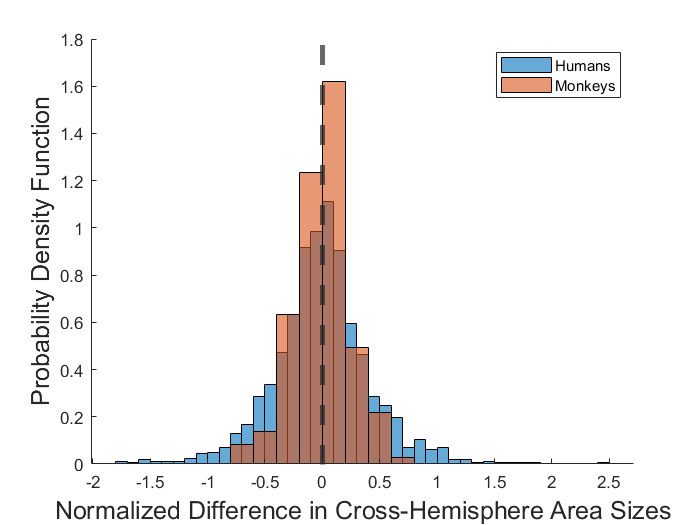


figure()
histogram(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'Normalization','pdf');
hold on;
histogram(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'Normalization','pdf');
xline(0,'--','linewidth',3)
box off
xlabel('Normalized Difference in Cross-Hemisphere Area Sizes','fontsize',15)
ylabel('Probability Density Function','fontsize',15)
legend('Humans','Monkeys')

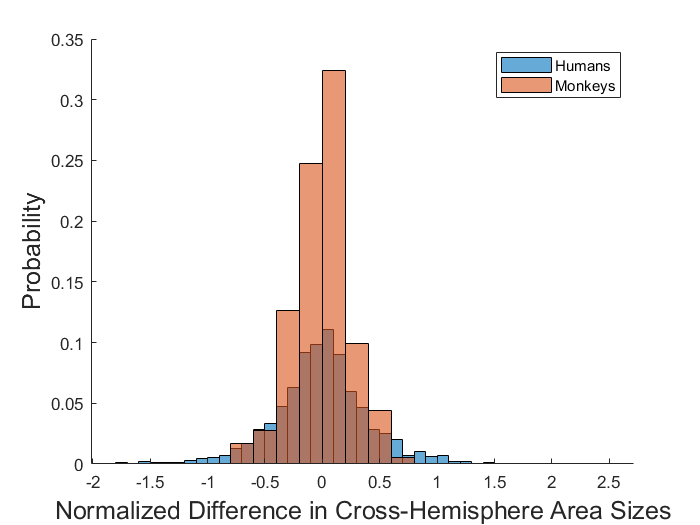

figure()
histogram(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'Normalization','probability');
hold on;
histogram(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'Normalization','probability');
box off
xlabel('Normalized Difference in Cross-Hemisphere Area Sizes','fontsize',15)
ylabel('Probability','fontsize',15)
legend('Humans','Monkeys')

## Supplementary Fig: Comparing Cross-Species Normalized Area Sizes

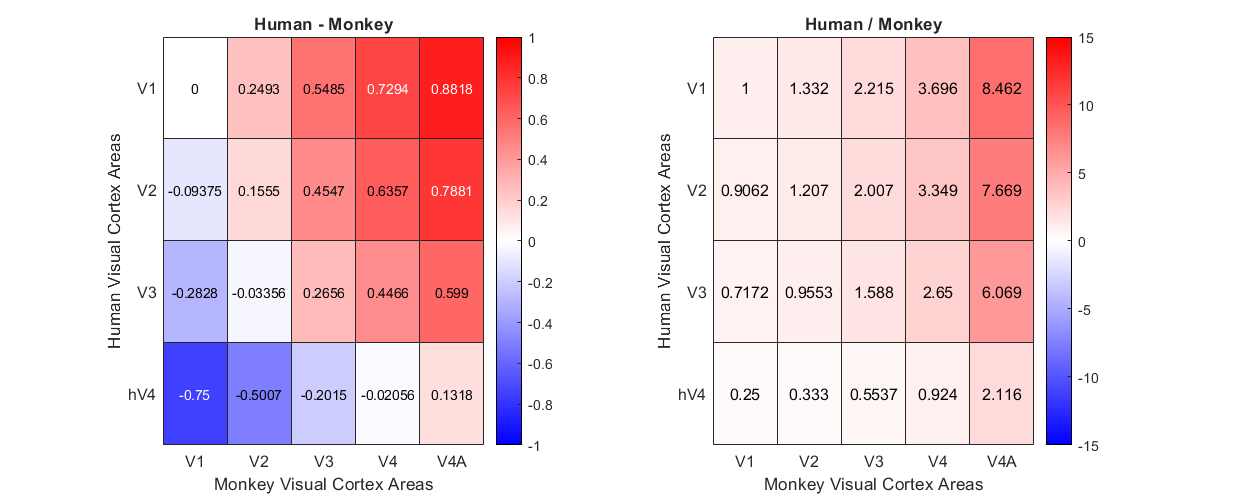

VCrois_human = {'V1','V2','V3','hV4'};
VCrois_monkey = {'V1','V2','V3','V4','V4A'};

ventralrois_monkey=6:10;
dorsalrois_monkey=11:12;
lateralrois_monkey=13:16;
parietalrois_monkey=17:21;

nhuman = length(VCrois_human);
nmonkey = length(VCrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(hh,:),'omitnan');
        avgmonkey = mean(normv1_monkey(mm,:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = VCrois_human;
xvalues = VCrois_monkey;

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-1 1]);
xlabel('Monkey Visual Cortex Areas')
ylabel('Human Visual Cortex Areas')
title('Human - Monkey')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Visual Cortex Areas')
ylabel('Human Visual Cortex Areas')
title('Human / Monkey')
saveas(gcf,[save_folder,'\CrossSpecies\visual_diff.png'])

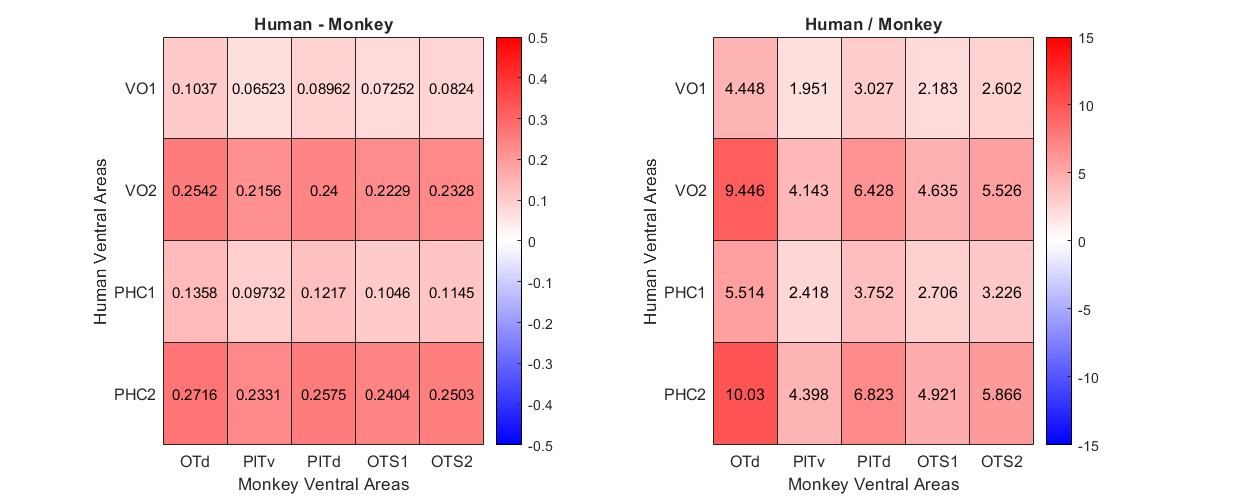

saveas(gcf,[save_folder,'\CrossSpecies\visual_diff.fig'])


% ventral rois
nhuman = length(ventralrois_human);
nmonkey = length(ventralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(ventralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(ventralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(ventralrois_human);
xvalues = alllabels_monkey(ventralrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Ventral Areas')
ylabel('Human Ventral Areas')
title('Human - Monkey')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Ventral Areas')
ylabel('Human Ventral Areas')
title('Human / Monkey')
saveas(gcf,[save_folder,'\CrossSpecies\ventral_diff.png'])

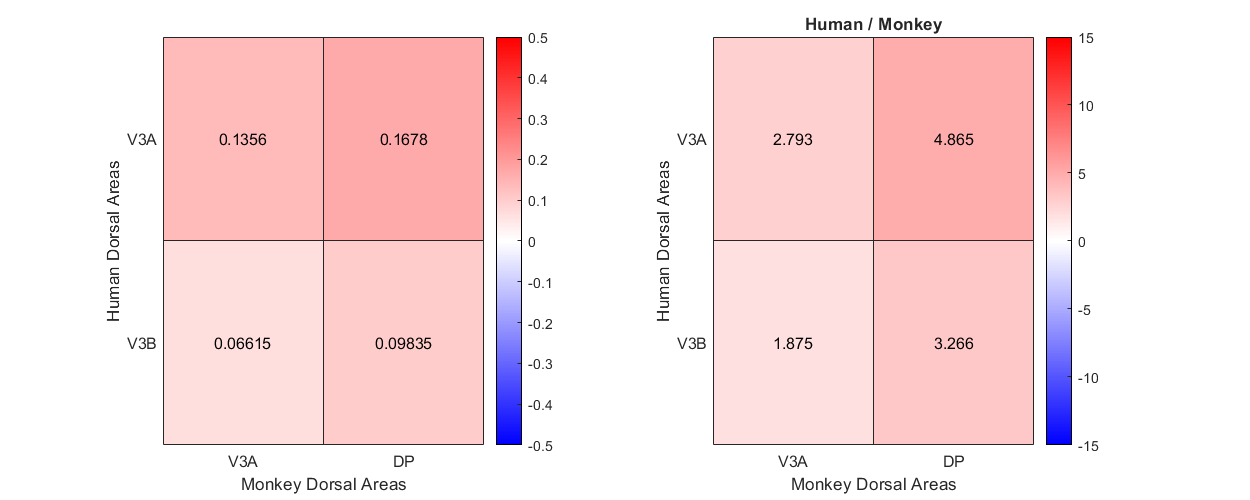

saveas(gcf,[save_folder,'\CrossSpecies\ventral_diff.fig'])
% dorsal rois
nhuman = length(dorsalrois_human)-1;
nmonkey = length(dorsalrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(dorsalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(dorsalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(dorsalrois_human(1:2));
xvalues = alllabels_monkey(dorsalrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1);
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Dorsal Areas')
ylabel('Human Dorsal Areas')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Dorsal Areas')
ylabel('Human Dorsal Areas')
title('Human / Monkey')
saveas(gcf,[save_folder,'\CrossSpecies\dorsal_diff.png'])

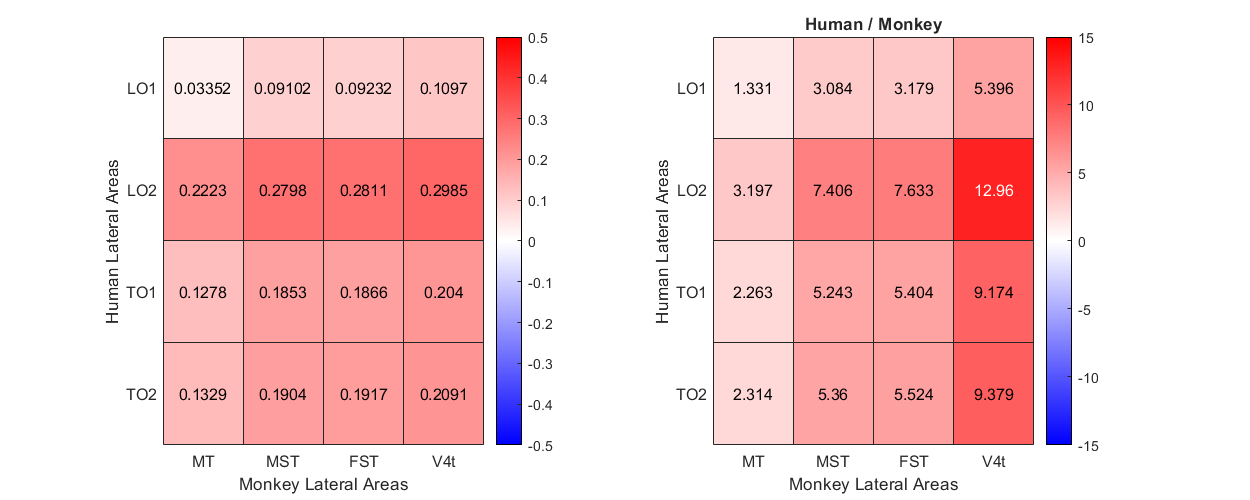

saveas(gcf,[save_folder,'\CrossSpecies\dorsal_diff.fig'])

% lateral rois
nhuman = length(lateralrois_human);
nmonkey = length(lateralrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(lateralrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(lateralrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(lateralrois_human);
xvalues = alllabels_monkey(lateralrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1);
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Lateral Areas')
ylabel('Human Lateral Areas')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Lateral Areas')
ylabel('Human Lateral Areas')
title('Human / Monkey')
saveas(gcf,[save_folder,'\CrossSpecies\lateral_diff.png'])

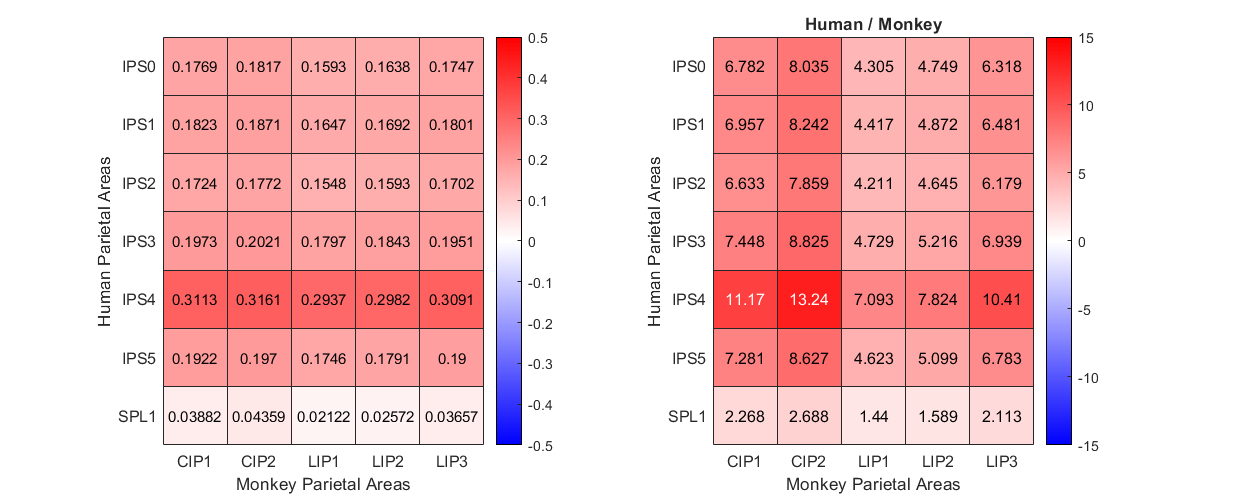

saveas(gcf,[save_folder,'\CrossSpecies\lateral_diff.fig'])


% parietal rois
nhuman = length(parietalrois_human);
nmonkey = length(parietalrois_monkey);

roi_diff = zeros(nhuman,nmonkey);
roi_div = zeros(nhuman,nmonkey);
for hh = 1:nhuman
    for mm = 1:nmonkey
        avghuman = mean(normv1_human(parietalrois_human(hh),:),'omitnan');
        avgmonkey = mean(normv1_monkey(parietalrois_monkey(mm),:),'omitnan');
        roi_diff(hh,mm) = avghuman - avgmonkey;
        roi_div(hh,mm) = avghuman / avgmonkey;
    end
end

yvalues = alllabels_human(parietalrois_human);
xvalues = alllabels_monkey(parietalrois_monkey);

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1);
h = heatmap(xvalues,yvalues,roi_diff);
colormap(redblue);colorbar;caxis([-0.5 0.5]);
xlabel('Monkey Parietal Areas')
ylabel('Human Parietal Areas')

subplot(1,2,2)
h = heatmap(xvalues,yvalues,roi_div);
colormap(redblue);colorbar;caxis([-15 15]);
xlabel('Monkey Parietal Areas')
ylabel('Human Parietal Areas')
title('Human / Monkey')
saveas(gcf,[save_folder,'\CrossSpecies\parietal_diff.png'])

saveas(gcf,[save_folder,'\CrossSpecies\parietal_diff.fig'])


## Cortical Distance Measurements

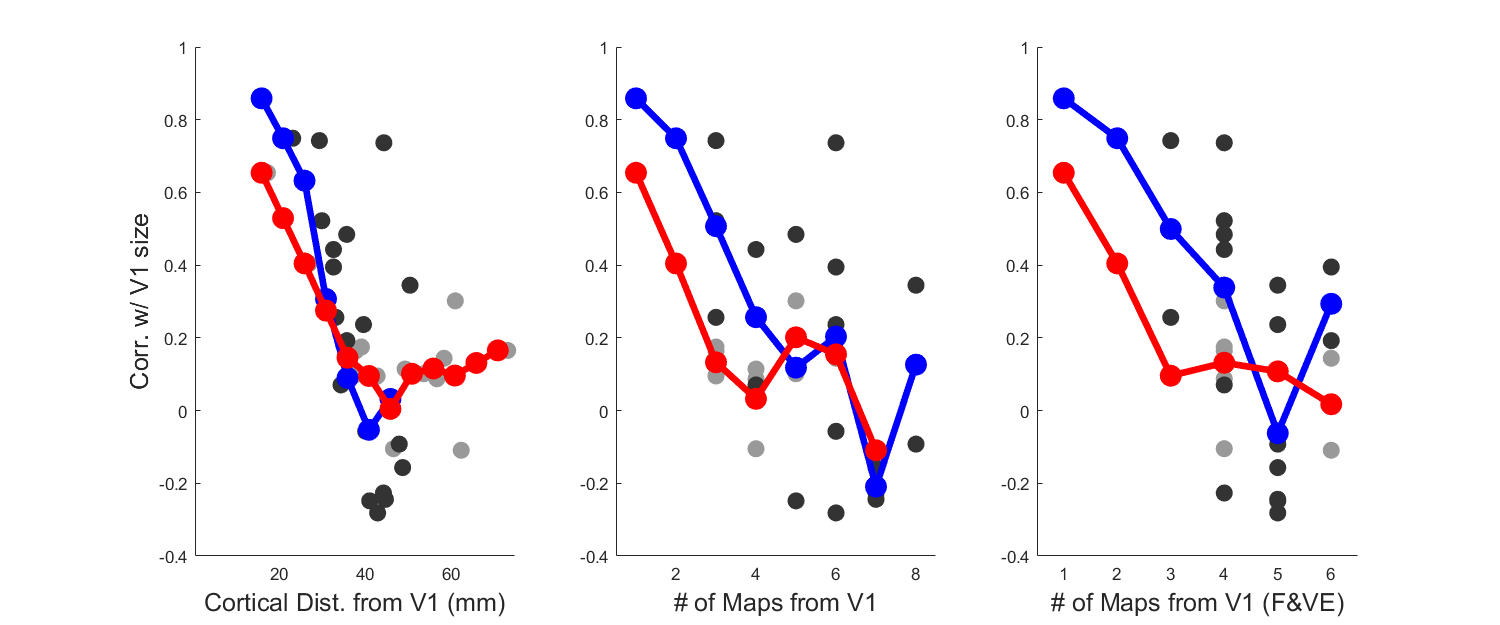

addpath(genpath('matlabfunctions'))
humans=load('Humans/alldata.mat');
monks=load('Monks/alldata.mat');

monks_cortdist=load('Monks/intermediate_files');
humans_cortdist=load('Humans/intermediate_files');
meanmonks_cortdist_rh=nanmean(monks_cortdist.avgdist_allsubjs_rh,2);
meanhumans_cortdist_rh=nanmean(humans_cortdist.avgdist_allsubjs_rh,2);
meanmonks_cortdist_lh=nanmean(monks_cortdist.avgdist_allsubjs_lh,2);
meanhumans_cortdist_lh=nanmean(humans_cortdist.avgdist_allsubjs_lh,2);

meanmonks_cortdist_rh1234=[];
meanmonks_cortdist_rh1234(1)=[meanmonks_cortdist_rh(1)+meanmonks_cortdist_rh(2)];
meanmonks_cortdist_rh1234(2)=[meanmonks_cortdist_rh(3)+meanmonks_cortdist_rh(4)]/2;
meanmonks_cortdist_rh1234(3)=[meanmonks_cortdist_rh(5)+meanmonks_cortdist_rh(6)]/2;
meanmonks_cortdist_rh1234(4)=[meanmonks_cortdist_rh(7)+meanmonks_cortdist_rh(8)]/2;
meanmonks_cortdist_rh1234(5)=[meanmonks_cortdist_rh(9)+meanmonks_cortdist_rh(10)]/2;
meanmonks_cortdist_rh1234=[meanmonks_cortdist_rh1234,meanmonks_cortdist_rh(11:end)'];

meanmonks_cortdist_lh1234=[];
meanmonks_cortdist_lh1234(1)=[meanmonks_cortdist_lh(1)+meanmonks_cortdist_lh(2)];
meanmonks_cortdist_lh1234(2)=[meanmonks_cortdist_lh(3)+meanmonks_cortdist_lh(4)]/2;
meanmonks_cortdist_lh1234(3)=[meanmonks_cortdist_lh(5)+meanmonks_cortdist_lh(6)]/2;
meanmonks_cortdist_lh1234(4)=[meanmonks_cortdist_lh(7)+meanmonks_cortdist_lh(8)]/2;
meanmonks_cortdist_lh1234(5)=[meanmonks_cortdist_lh(9)+meanmonks_cortdist_lh(10)]/2;
meanmonks_cortdist_lh1234=[meanmonks_cortdist_lh1234,meanmonks_cortdist_lh(11:end)'];

meanmonks_cortdist1234=[meanmonks_cortdist_lh1234+meanmonks_cortdist_lh1234]/2;

meanhumans_cortdist_rh1234=[];
meanhumans_cortdist_rh1234(1)=[meanhumans_cortdist_rh(1)+meanhumans_cortdist_rh(2)];
meanhumans_cortdist_rh1234(2)=[meanhumans_cortdist_rh(3)+meanhumans_cortdist_rh(4)]/2;
meanhumans_cortdist_rh1234(3)=[meanhumans_cortdist_rh(5)+meanhumans_cortdist_rh(6)]/2;
meanhumans_cortdist_rh1234=[meanhumans_cortdist_rh1234,meanhumans_cortdist_rh(7:end)'];

meanhumans_cortdist_lh1234=[];
meanhumans_cortdist_lh1234(1)=[meanhumans_cortdist_lh(1)+meanhumans_cortdist_lh(2)];
meanhumans_cortdist_lh1234(2)=[meanhumans_cortdist_lh(3)+meanhumans_cortdist_lh(4)]/2;
meanhumans_cortdist_lh1234(3)=[meanhumans_cortdist_lh(5)+meanhumans_cortdist_lh(6)]/2;
meanhumans_cortdist_lh1234=[meanhumans_cortdist_lh1234,meanhumans_cortdist_lh(7:end)'];

meanhumans_cortdist1234=[meanhumans_cortdist_lh1234+meanhumans_cortdist_lh1234]/2;

human_labels =          {'V1', 'V2', 'V3','hV4','VO1','VO2','PHC1','PHC2', 'V3A','V3B','V7','LO1','LO2','TO1','TO2'}; 
human_areadistfromV1=    [0,     1,    2,   3,    4,   5,     6,      7,     3,    3,    4,   3,    4,    5,    6];
human_fellemanhierarchy=  [1,    2,    3,   5,    6,    6,    7,      7,     4,    4,    5,   5,     5,   5,    5]-1;

monk_labels =           {'V1', 'V2', 'V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','CIP1','CIP2','LIP1','LIP2','LIP3','MT','MST','FST','V4t'};
monk_areadistfromV1=      [0,    1,    2,   3,   4,   5,     6,    6,      6,      6,    3,    3,    4,    5,     6,     7,     8,     6,   7,    8,   7];
monk_fellemanhierarchy=   [1,    2,    3,   5,   5,   6,     6,    6,      7,      7,    4,    4,    5,     5,    6,     6,     6,     5,   6,    6,   5]-1;

monks_allareas=monks.V1_cat_corr1234;
humans_allareas=humans.V1_cat_corr1234;

for x = 1:max([monk_areadistfromV1,human_areadistfromV1])
    monk_meanareadist(x)=nanmean(monks_allareas(monk_areadistfromV1==x));
    human_meanareadist(x)=nanmean(humans_allareas(human_areadistfromV1==x));   
end

for x = 1:max([monk_fellemanhierarchy,human_fellemanhierarchy])
    monk_meanhierarchydist(x)=nanmean(monks_allareas(monk_fellemanhierarchy==x));
    human_meanhierarchydist(x)=nanmean(humans_allareas(human_fellemanhierarchy==x));   
end

stepsize=5;
maxrange=80;
monk_meancortdist=nan(length(1:stepsize:maxrange),1);
human_meancortdist=nan(length(1:stepsize:maxrange),1);
count = 0;
for x = 1:stepsize:maxrange
    count = count+1;
    if x < 80
        if sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]) > 1
            monk_meancortdist(count)=nanmean(monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<x+stepsize]));
        elseif sum([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)])
            monk_meancortdist(count)=monks_allareas([meanmonks_cortdist1234>=x & meanmonks_cortdist1234<(x+stepsize)]);
        end
        if sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]) > 1
            human_meancortdist(count)=nanmean(humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]));
        elseif sum([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)])
            human_meancortdist(count)=humans_allareas([meanhumans_cortdist1234>=x & meanhumans_cortdist1234<(x+stepsize)]);
        end
    end
end
human_meancortdist(5)=[human_meancortdist(4)+human_meancortdist(6)]/2;
human_meancortdist(7)=[human_meancortdist(6)+human_meancortdist(8)]/2;
human_meancortdist(14)=[human_meancortdist(13)+human_meancortdist(15)]/2;

figure('Renderer', 'painters', 'Position', [10 10 1200 500])
subplot(1,3,1) 
hold on
plot(meanhumans_cortdist1234(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',35)
plot(meanmonks_cortdist1234(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',35) 
plot(1:stepsize:maxrange,monk_meancortdist,'.-b','MarkerSize',45,'LineWidth',4)
plot(1:stepsize:maxrange,human_meancortdist,'.-r','MarkerSize',45,'LineWidth',4)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
xlim([0.5 75])
xlabel('Cortical Dist. from V1 (mm)','fontsize',15)
ylabel('Corr. w/ V1 size','fontsize',15)

subplot(1,3,2)
hold on
plot(human_areadistfromV1(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',35)
plot(monk_areadistfromV1(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',35) 
plot(monk_meanareadist,'.-b','MarkerSize',45,'LineWidth',4)
plot(human_meanareadist,'.-r','MarkerSize',45,'LineWidth',4)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
xlim([0.5 max([monk_areadistfromV1,human_areadistfromV1])+.5])
xlabel('# of Maps from V1','Fontsize',15)
 
subplot(1,3,3)
hold on
plot(human_fellemanhierarchy(2:end),humans_allareas(2:end),'.','color',[.6 .6 .6],'MarkerSize',35)
plot(monk_fellemanhierarchy(2:end),monks_allareas(2:end),'.','color',[.2 .2 .2],'MarkerSize',35) 
plot(monk_meanhierarchydist,'.-b','MarkerSize',45,'LineWidth',4)
plot(human_meanhierarchydist,'.-r','MarkerSize',45,'LineWidth',4)
box off
ax = gca;
ax.XAxis.TickLength = [0 0];
xlim([0.5 max([monk_fellemanhierarchy,human_fellemanhierarchy])+.5])
xlabel('# of Maps from V1 (F&VE)','Fontsize',15)